# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(david_file_path + "test_config.json");
sim_config = jsondecode(json_text);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

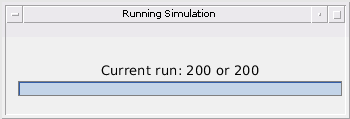

target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges =   135.5173       NaN       NaN       NaN       NaN
  135.1652       NaN       NaN       NaN       NaN
  134.3053       NaN       NaN       NaN       NaN
  133.8407       NaN       NaN       NaN       NaN
  133.2433       NaN       NaN       NaN       NaN
  134.0226       NaN       NaN       NaN       NaN
  113.7717       NaN       NaN       NaN       NaN
  114.2592       NaN       NaN       NaN       NaN
  114.8466       NaN       NaN       NaN       NaN
  110.8202       NaN       NaN       NaN       NaN


actual_ranges =   130.0000  130.5002  131.0005  131.5007  132.0009  132.5011  133.0014  133.5016  134.0018  134.5021


estimated_velocities =   -14.9371       NaN       NaN       NaN       NaN
  -14.9621       NaN       NaN       NaN       NaN
  -14.9828       NaN       NaN       NaN       NaN
  -14.9708       NaN       NaN       NaN       NaN
  -14.9811       NaN       NaN       NaN       NaN
  -14.9639       NaN       NaN       NaN       NaN
  -14.9597       NaN       NaN       NaN       NaN
  -15.0690       NaN       NaN       NaN       NaN
  -15.0422       NaN       NaN       NaN       NaN
  -14.9920       NaN       NaN       NaN       NaN


actual_velocities =    -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected =      1     1     1     1     1     1     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges =     5.5173
    4.6649
    3.3049
    2.3400
    1.2424
    1.5214
         0
         0
         0
         0


percent_error_velocities =     0.0629
    0.0379
    0.0172
    0.0292
    0.0189
    0.0361
         0
         0
         0
         0


target_velocity = 12

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges =   141.7760       NaN       NaN       NaN       NaN
  140.2703       NaN       NaN       NaN       NaN
  140.3460       NaN       NaN       NaN       NaN
  138.5275       NaN       NaN       NaN       NaN
  138.2349       NaN       NaN       NaN       NaN
  139.0627       NaN       NaN       NaN       NaN
  119.9683       NaN       NaN       NaN       NaN
  120.6116       NaN       NaN       NaN       NaN
  121.7297       NaN       NaN       NaN       NaN
  117.9899  117.9851       NaN       NaN       NaN


actual_ranges =   135.0000  135.3335  135.6670  136.0005  136.3339  136.6674  137.0009  137.3344  137.6679  138.0014


estimated_velocities =    -9.9522       NaN       NaN       NaN       NaN
   -9.9849       NaN       NaN       NaN       NaN
   -9.9749       NaN       NaN       NaN       NaN
   -9.9876       NaN       NaN       NaN       NaN
   -9.9764       NaN       NaN       NaN       NaN
   -9.8996       NaN       NaN       NaN       NaN
   -9.9832       NaN       NaN       NaN       NaN
  -10.0148       NaN       NaN       NaN       NaN
   -9.9451       NaN       NaN       NaN       NaN
  -20.3579   -9.8629       NaN       NaN       NaN


actual_velocities =    -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected =      1     1     1     1     1     1     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges =     6.7760
    4.9368
    4.6791
    2.5271
    1.9009
    2.3953
         0
         0
         0
         0


percent_error_velocities =     0.0478
    0.0151
    0.0251
    0.0124
    0.0236
    0.1004
         0
         0
         0
         0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges =    NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges =    15.0000   14.4998   13.9995   13.4993   12.9991   12.4989   11.9986   11.4984   10.9982   10.4979


estimated_velocities =    NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities =     15    15    15    15    15    15    15    15    15    15


detected =      0     0     0     0     0     0     0     0     0     0


col_detection =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges =   141.8012       NaN       NaN       NaN       NaN
  140.5102       NaN       NaN       NaN       NaN
  140.3343       NaN       NaN       NaN       NaN
  139.6417       NaN       NaN       NaN       NaN
  138.3742       NaN       NaN       NaN       NaN
  139.2408  139.4769       NaN       NaN       NaN
  119.5560  119.7358  119.6754       NaN       NaN
  120.6170       NaN       NaN       NaN       NaN
  120.7200       NaN       NaN       NaN       NaN
  115.2180       NaN       NaN       NaN       NaN


actual_ranges =   135.0000  135.2001  135.4002  135.6003  135.8004  136.0005  136.2005  136.4006  136.6007  136.8008


estimated_velocities =    -5.9559       NaN       NaN       NaN       NaN
   -5.9881       NaN       NaN       NaN       NaN
   -6.0294       NaN       NaN       NaN       NaN
   -6.0712       NaN       NaN       NaN       NaN
   -6.0318       NaN       NaN       NaN       NaN
  -32.7097   -6.0765       NaN       NaN       NaN
   16.1409    9.3862   -6.0058       NaN       NaN
   -6.0025       NaN       NaN       NaN       NaN
   -5.9882       NaN       NaN       NaN       NaN
   -5.9594       NaN       NaN       NaN       NaN


actual_velocities =     -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected =      1     1     1     1     1     1     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges =     6.8012
    5.3101
    4.9342
    4.0414
    2.5738
         0
         0
         0
         0
         0


percent_error_velocities =     0.0441
    0.0119
    0.0294
    0.0712
    0.0318
         0
         0
         0
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges =    76.4984       NaN       NaN       NaN       NaN
   77.2180       NaN       NaN       NaN       NaN
   77.8515       NaN       NaN       NaN       NaN
   79.4311       NaN       NaN       NaN       NaN
   81.2237       NaN       NaN       NaN       NaN
   71.6155       NaN       NaN       NaN       NaN
   50.9704       NaN       NaN       NaN       NaN
   51.4529   51.3767       NaN       NaN       NaN
   51.9307   51.9860       NaN       NaN       NaN
   46.4976       NaN       NaN       NaN       NaN


actual_ranges =    75.0000   74.6665   74.3330   73.9995   73.6661   73.3326   72.9991   72.6656   72.3321   71.9986


estimated_velocities =     9.9798       NaN       NaN       NaN       NaN
    9.9709       NaN       NaN       NaN       NaN
    9.9738       NaN       NaN       NaN       NaN
    9.9746       NaN       NaN       NaN       NaN
    9.9438       NaN       NaN       NaN       NaN
   10.0092       NaN       NaN       NaN       NaN
    9.9534       NaN       NaN       NaN       NaN
  -25.9018    9.9308       NaN       NaN       NaN
   -6.3412    9.9473       NaN       NaN       NaN
    9.9031       NaN       NaN       NaN       NaN


actual_velocities =     10    10    10    10    10    10    10    10    10    10


detected =      1     1     1     1     1     1     0     0     0     0


col_detection =      1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives =      0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges =     1.4984
    2.5515
    3.5185
    5.4315
    7.5576
    1.7171
         0
         0
         0
         0


percent_error_velocities =     0.0202
    0.0291
    0.0262
    0.0254
    0.0562
    0.0092
         0
         0
         0
         0


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges =    58.4701       NaN       NaN       NaN       NaN
   58.5362       NaN       NaN       NaN       NaN
   69.6546       NaN       NaN       NaN       NaN
   69.3838       NaN       NaN       NaN       NaN
   68.9192       NaN       NaN       NaN       NaN
   66.2748       NaN       NaN       NaN       NaN
   44.7407   44.8035       NaN       NaN       NaN
   44.8023       NaN       NaN       NaN       NaN
   45.4879   45.4876       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN


actual_ranges =    63.0000   63.3001   63.6003   63.9004   64.2005   64.5007   64.8008   65.1010   65.4011   65.7012


estimated_velocities =    -9.0230       NaN       NaN       NaN       NaN
   -9.0203       NaN       NaN       NaN       NaN
   -9.0471       NaN       NaN       NaN       NaN
   -9.0217       NaN       NaN       NaN       NaN
   -9.0296       NaN       NaN       NaN       NaN
   -9.0141       NaN       NaN       NaN       NaN
    0.1405   -9.0642       NaN       NaN       NaN
   -9.0281       NaN       NaN       NaN       NaN
  -26.4418   -9.0372       NaN       NaN       NaN
   -9.0250       NaN       NaN       NaN       NaN


actual_velocities =     -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected =      1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.5299
    4.7639
    6.0543
    5.4834
    4.7187
    1.7741
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0230
    0.0203
    0.0471
    0.0217
    0.0296
    0.0141
         0
         0
         0
         0


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  136.9862       NaN       NaN       NaN       NaN
  126.5482       NaN       NaN       NaN       NaN
  128.3859       NaN       NaN       NaN       NaN
  129.3284       NaN       NaN       NaN       NaN
  130.9721       NaN       NaN       NaN       NaN
  134.1448       NaN       NaN       NaN       NaN
  113.3037       NaN       NaN       NaN       NaN
  109.0367       NaN       NaN       NaN       NaN
  110.1491       NaN       NaN       NaN       NaN
  104.9981  105.0228  105.1288       NaN       NaN


actual_ranges = 1×10
  135.0000  133.9995  132.9991  131.9986  130.9982  129.9977  128.9973  127.9968  126.9963  125.9959


estimated_velocities = 10×5
   30.0631       NaN       NaN       NaN       NaN
   29.9277       NaN       NaN       NaN       NaN
   30.0537       NaN       NaN       NaN       NaN
   30.0578       NaN       NaN       NaN       NaN
   29.9982       NaN       NaN       NaN       NaN
   30.0685       NaN       NaN       NaN       NaN
   30.0887       NaN       NaN       NaN       NaN
   30.0291       NaN       NaN       NaN       NaN
   29.9505       NaN       NaN       NaN       NaN
  -29.9311   30.0255   -5.0496       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.9862
    7.4513
    4.6132
    2.6702
    0.0261
    4.1471
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0631
    0.0723
    0.0537
    0.0578
    0.0018
    0.0685
         0
         0
         0
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  121.0527       NaN       NaN       NaN       NaN
  123.6795       NaN       NaN       NaN       NaN
  125.3183       NaN       NaN       NaN       NaN
  126.0266       NaN       NaN       NaN       NaN
  126.8671       NaN       NaN       NaN       NaN
  128.3934       NaN       NaN       NaN       NaN
  108.4471       NaN       NaN       NaN       NaN
  104.3643  104.3557       NaN       NaN       NaN
  104.7148  104.6569       NaN       NaN       NaN
   99.5533       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  129.0000  128.2330  127.4660  126.6989  125.9319  125.1649  124.3979  123.6309  122.8639  122.0968


estimated_velocities = 10×5
   23.0029       NaN       NaN       NaN       NaN
   22.9604       NaN       NaN       NaN       NaN
   23.0052       NaN       NaN       NaN       NaN
   22.9797       NaN       NaN       NaN       NaN
   22.9661       NaN       NaN       NaN       NaN
   22.9385       NaN       NaN       NaN       NaN
   22.9421       NaN       NaN       NaN       NaN
   33.8717   22.9432       NaN       NaN       NaN
    9.2609   22.9583       NaN       NaN       NaN
   23.0615       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    7.9473
    4.5535
    2.1476
    0.6723
    0.9352
    3.2285
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0029
    0.0396
    0.0052
    0.0203
    0.0339
    0.0615
         0
         0
         0
         0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   16.0000   16.9004   17.8008   18.7012   19.6016   20.5021   21.4025   22.3029   23.2033   24.1037


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   99.5559       NaN       NaN       NaN       NaN
   98.8340       NaN       NaN       NaN       NaN
   98.4812       NaN       NaN       NaN       NaN
   97.4136       NaN       NaN       NaN       NaN
   97.0164       NaN       NaN       NaN       NaN
  102.9628       NaN       NaN       NaN       NaN
   83.1508       NaN       NaN       NaN       NaN
   89.4734       NaN       NaN       NaN       NaN
   89.8927       NaN       NaN       NaN       NaN
   84.5131   84.4523       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  103.2334  103.4669  103.7003  103.9338  104.1672  104.4006  104.6341  104.8675  105.1010


estimated_velocities = 10×5
   -6.9578       NaN       NaN       NaN       NaN
   -6.9667       NaN       NaN       NaN       NaN
   -6.9636       NaN       NaN       NaN       NaN
   -6.9234       NaN       NaN       NaN       NaN
   -7.0251       NaN       NaN       NaN       NaN
   -6.9549       NaN       NaN       NaN       NaN
   -6.9678       NaN       NaN       NaN       NaN
   -6.9210       NaN       NaN       NaN       NaN
   -6.9604       NaN       NaN       NaN       NaN
    1.1675   -6.9821       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.4441
    4.3995
    4.9856
    6.2867
    6.9174
    1.2044
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0422
    0.0333
    0.0364
    0.0766
    0.0251
    0.0451
         0
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   17.0000   17.5336   18.0672   18.6007   19.1343   19.6679   20.2015   20.7350   21.2686   21.8022


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   29.0000   29.4669   29.9338   30.4006   30.8675   31.3344   31.8013   32.2682   32.7350   33.2019


estimated_velocities = 10×5
  -14.0337       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -14.0311       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  135.0643       NaN       NaN       NaN       NaN
  135.6131       NaN       NaN       NaN       NaN
  136.0501       NaN       NaN       NaN       NaN
  136.2277       NaN       NaN       NaN       NaN
  136.8326       NaN       NaN       NaN       NaN
  138.8691  139.0394       NaN       NaN       NaN
  119.5074       NaN       NaN       NaN       NaN
  120.3270       NaN       NaN       NaN       NaN
  120.7220       NaN       NaN       NaN       NaN
  111.1966       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  138.0000  137.5665  137.1329  136.6994  136.2659  135.8323  135.3988  134.9653  134.5317  134.0982


estimated_velocities = 10×5
   13.0196       NaN       NaN       NaN       NaN
   12.9787       NaN       NaN       NaN       NaN
   12.9810       NaN       NaN       NaN       NaN
   12.9977       NaN       NaN       NaN       NaN
   12.9820       NaN       NaN       NaN       NaN
   -1.6642   12.9579       NaN       NaN       NaN
   12.9855       NaN       NaN       NaN       NaN
   12.9756       NaN       NaN       NaN       NaN
   13.0023       NaN       NaN       NaN       NaN
   12.9857       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.9357
    1.9534
    1.0828
    0.4717
    0.5667
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0196
    0.0213
    0.0190
    0.0023
    0.0180
         0
         0
         0
         0
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   51.0260       NaN       NaN       NaN       NaN
   52.4902       NaN       NaN       NaN       NaN
   53.3853       NaN       NaN       NaN       NaN
   54.1304       NaN       NaN       NaN       NaN
   55.3573       NaN       NaN       NaN       NaN
   55.1860   55.5698       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.3654       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   58.0000   57.1663   56.3326   55.4989   54.6651   53.8314   52.9977   52.1640   51.3303   50.4966


estimated_velocities = 10×5
   25.0046       NaN       NaN       NaN       NaN
   25.0003       NaN       NaN       NaN       NaN
   25.0134       NaN       NaN       NaN       NaN
   25.0091       NaN       NaN       NaN       NaN
   25.0124       NaN       NaN       NaN       NaN
   16.6661   24.9476       NaN       NaN       NaN
   24.9930       NaN       NaN       NaN       NaN
   25.0946       NaN       NaN       NaN       NaN
   25.0262       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    6.9740
    4.6761
    2.9473
    1.3684
    0.6921
    1.3545
    4.2835
    3.4498
    2.9649
         0


percent_error_velocities = 10×1
    0.0046
    0.0003
    0.0134
    0.0091
    0.0124
    8.3339
    0.0070
    0.0946
    0.0262
         0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  111.8376       NaN       NaN       NaN       NaN
  112.8921       NaN       NaN       NaN       NaN
  114.0036       NaN       NaN       NaN       NaN
  115.0556       NaN       NaN       NaN       NaN
  115.5874       NaN       NaN       NaN       NaN
  118.3914       NaN       NaN       NaN       NaN
   97.5126       NaN       NaN       NaN       NaN
   98.0517       NaN       NaN       NaN       NaN
   93.4326   93.4297   93.4796       NaN       NaN
   89.3550   89.3735       NaN       NaN       NaN


actual_ranges = 1×10
  119.0000  118.3330  117.6661  116.9991  116.3321  115.6651  114.9982  114.3312  113.6642  112.9973


estimated_velocities = 10×5
   19.9735       NaN       NaN       NaN       NaN
   19.9568       NaN       NaN       NaN       NaN
   19.9676       NaN       NaN       NaN       NaN
   19.9753       NaN       NaN       NaN       NaN
   19.9608       NaN       NaN       NaN       NaN
   19.9277       NaN       NaN       NaN       NaN
   19.9810       NaN       NaN       NaN       NaN
   20.0126       NaN       NaN       NaN       NaN
   32.7229   19.9531   -1.6310       NaN       NaN
  -10.6836   19.9060       NaN       NaN       NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    7.1624
    5.4409
    3.6625
    1.9434
    0.7447
    2.7263
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0265
    0.0432
    0.0324
    0.0247
    0.0392
    0.0723
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   67.1284       NaN       NaN       NaN       NaN
   67.1700       NaN       NaN       NaN       NaN
   67.1754       NaN       NaN       NaN       NaN
   67.1662       NaN       NaN       NaN       NaN
   67.1664       NaN       NaN       NaN       NaN
   66.0879   65.5675       NaN       NaN       NaN
   45.6064       NaN       NaN       NaN       NaN
   46.0381       NaN       NaN       NaN       NaN
   46.1687   46.1438   46.1943       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    65    65    65    65    65    65    65    65    65    65


estimated_velocities = 10×5
   -0.0024       NaN       NaN       NaN       NaN
    0.0049       NaN       NaN       NaN       NaN
   -0.0016       NaN       NaN       NaN       NaN
    0.0026       NaN       NaN       NaN       NaN
   -0.0015       NaN       NaN       NaN       NaN
  -30.6442    0.0574       NaN       NaN       NaN
   -0.0628       NaN       NaN       NaN       NaN
    0.0608       NaN       NaN       NaN       NaN
   30.4943   -0.0173  -30.3827       NaN       NaN
    0.0033       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.1284
    2.1700
    2.1754
    2.1662
    2.1664
    0.5675
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0024
    0.0049
    0.0016
    0.0026
    0.0015
    0.0574
         0
         0
         0
         0


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   41.2197       NaN       NaN       NaN       NaN
   44.8228       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   39.0000   37.9995   36.9991   35.9986   34.9982   33.9977   32.9973   31.9968   30.9963   29.9959


estimated_velocities = 10×5
   30.0234       NaN       NaN       NaN       NaN
   30.0218       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   29.9851       NaN       NaN       NaN       NaN
   30.0189       NaN       NaN       NaN       NaN
   29.9668       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     0     0     0     0     0     0     0     0


col_detection = 10×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.2197
    6.8233
         0
         0
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0234
    0.0218
         0
         0
         0
         0
         0
         0
         0
         0


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   58.9992       NaN       NaN       NaN       NaN
   59.9438       NaN       NaN       NaN       NaN
   61.7962       NaN       NaN       NaN       NaN
   50.9350       NaN       NaN       NaN       NaN
   52.6360       NaN       NaN       NaN       NaN
   54.2161       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   48.3107       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   61.0000   59.9328   58.8657   57.7985   56.7314   55.6642   54.5971   53.5299   52.4628   51.3956


estimated_velocities = 10×5
   32.0171       NaN       NaN       NaN       NaN
   32.0213       NaN       NaN       NaN       NaN
   32.0288       NaN       NaN       NaN       NaN
   32.0172       NaN       NaN       NaN       NaN
   32.0254       NaN       NaN       NaN       NaN
   31.9760       NaN       NaN       NaN       NaN
   32.0332       NaN       NaN       NaN       NaN
   32.0488       NaN       NaN       NaN       NaN
   32.0508       NaN       NaN       NaN       NaN
   32.0439       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     1     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0


percent_error_ranges = 10×1
    2.0008
    0.0110
    2.9305
    6.8636
    4.0953
    1.4482
    5.8829
    4.8158
         0
    3.0849


percent_error_velocities = 10×1
    0.0171
    0.0213
    0.0288
    0.0172
    0.0254
    0.0240
    0.0332
    0.0488
         0
    0.0439


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  120.7575       NaN       NaN       NaN       NaN
  119.4141       NaN       NaN       NaN       NaN
  119.0807       NaN       NaN       NaN       NaN
  118.3358       NaN       NaN       NaN       NaN
  116.4015       NaN       NaN       NaN       NaN
  118.3393       NaN       NaN       NaN       NaN
   98.1913       NaN       NaN       NaN       NaN
  104.2776       NaN       NaN       NaN       NaN
  104.9392       NaN       NaN       NaN       NaN
   99.3128       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  115.0000  115.8004  116.6007  117.4011  118.2015  119.0018  119.8022  120.6026  121.4029  122.2033


estimated_velocities = 10×5
  -24.0114       NaN       NaN       NaN       NaN
  -24.0189       NaN       NaN       NaN       NaN
  -24.0048       NaN       NaN       NaN       NaN
  -24.0182       NaN       NaN       NaN       NaN
  -24.0216       NaN       NaN       NaN       NaN
  -24.0090       NaN       NaN       NaN       NaN
  -24.0062       NaN       NaN       NaN       NaN
  -23.9837       NaN       NaN       NaN       NaN
  -24.0633       NaN       NaN       NaN       NaN
  -24.0397       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.7575
    3.6138
    2.4800
    0.9347
    1.8000
    0.6625
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0114
    0.0189
    0.0048
    0.0182
    0.0216
    0.0090
         0
         0
         0
         0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   85.3208       NaN       NaN       NaN       NaN
   89.4485       NaN       NaN       NaN       NaN
   76.5049       NaN       NaN       NaN       NaN
   78.4528       NaN       NaN       NaN       NaN
   80.1510       NaN       NaN       NaN       NaN
   81.7862   81.5706       NaN       NaN       NaN
   60.5500   60.2916       NaN       NaN       NaN
   55.6731   55.6642       NaN       NaN       NaN
   55.9592       NaN       NaN       NaN       NaN
   51.7812       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   83.8661   82.7323   81.5984   80.4646   79.3307   78.1969   77.0630   75.9292   74.7953


estimated_velocities = 10×5
   33.9869       NaN       NaN       NaN       NaN
   33.9465       NaN       NaN       NaN       NaN
   34.0028       NaN       NaN       NaN       NaN
   33.9873       NaN       NaN       NaN       NaN
   33.9760       NaN       NaN       NaN       NaN
   17.9396   34.0032       NaN       NaN       NaN
  -25.3748   33.9933       NaN       NaN       NaN
   19.6071   33.9881       NaN       NaN       NaN
   33.9398       NaN       NaN       NaN       NaN
   33.9477       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.3208
    5.5824
    6.2274
    3.1456
    0.3136
    2.2398
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0131
    0.0535
    0.0028
    0.0127
    0.0240
    0.0032
         0
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  117.7753       NaN       NaN       NaN       NaN
  117.5110       NaN       NaN       NaN       NaN
  116.1514       NaN       NaN       NaN       NaN
  113.0765       NaN       NaN       NaN       NaN
  128.2551       NaN       NaN       NaN       NaN
  118.5507       NaN       NaN       NaN       NaN
  103.8751       NaN       NaN       NaN       NaN
  104.4740       NaN       NaN       NaN       NaN
  104.8623       NaN       NaN       NaN       NaN
   99.5414   99.5754       NaN       NaN       NaN


actual_ranges = 1×10
  117.0000  117.5669  118.1339  118.7008  119.2677  119.8346  120.4016  120.9685  121.5354  122.1023


estimated_velocities = 10×5
  -17.0253       NaN       NaN       NaN       NaN
  -16.9876       NaN       NaN       NaN       NaN
  -16.9630       NaN       NaN       NaN       NaN
  -17.0323       NaN       NaN       NaN       NaN
  -16.8722       NaN       NaN       NaN       NaN
  -17.0849       NaN       NaN       NaN       NaN
  -16.9947       NaN       NaN       NaN       NaN
  -17.0619       NaN       NaN       NaN       NaN
  -17.0787       NaN       NaN       NaN       NaN
   34.6655  -17.0680       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.7753
    0.0559
    1.9824
    5.6243
    8.9874
    1.2839
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0253
    0.0124
    0.0370
    0.0323
    0.1278
    0.0849
         0
         0
         0
         0


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   96.9827       NaN       NaN       NaN       NaN
   96.3566       NaN       NaN       NaN       NaN
   95.6806       NaN       NaN       NaN       NaN
   94.9826       NaN       NaN       NaN       NaN
   92.8110       NaN       NaN       NaN       NaN
   97.3131       NaN       NaN       NaN       NaN
   76.3618       NaN       NaN       NaN       NaN
   82.4885       NaN       NaN       NaN       NaN
   82.7325   82.6634       NaN       NaN       NaN
   77.3467       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   97.0000   97.4335   97.8671   98.3006   98.7341   99.1677   99.6012  100.0347  100.4683  100.9018


estimated_velocities = 10×5
  -12.9901       NaN       NaN       NaN       NaN
  -12.9911       NaN       NaN       NaN       NaN
  -12.9722       NaN       NaN       NaN       NaN
  -13.0297       NaN       NaN       NaN       NaN
  -12.9820       NaN       NaN       NaN       NaN
  -13.0622       NaN       NaN       NaN       NaN
  -12.9735       NaN       NaN       NaN       NaN
  -12.9085       NaN       NaN       NaN       NaN
   12.2680  -13.0665       NaN       NaN       NaN
  -12.9981       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0173
    1.0769
    2.1865
    3.3180
    5.9231
    1.8546
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0099
    0.0089
    0.0278
    0.0297
    0.0180
    0.0622
         0
         0
         0
         0


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   96.7284       NaN       NaN       NaN       NaN
   97.3825       NaN       NaN       NaN       NaN
   98.8248       NaN       NaN       NaN       NaN
   99.5437       NaN       NaN       NaN       NaN
  102.5742       NaN       NaN       NaN       NaN
  102.5281       NaN       NaN       NaN       NaN
   76.5460       NaN       NaN       NaN       NaN
   77.5753       NaN       NaN       NaN       NaN
   78.2434       NaN       NaN       NaN       NaN
   73.8150   73.8870       NaN       NaN       NaN


actual_ranges = 1×10
  104.0000  102.9662  101.9324  100.8986   99.8648   98.8310   97.7972   96.7634   95.7295   94.6957


estimated_velocities = 10×5
   30.9330       NaN       NaN       NaN       NaN
   30.9626       NaN       NaN       NaN       NaN
   30.9707       NaN       NaN       NaN       NaN
   30.9722       NaN       NaN       NaN       NaN
   30.9714       NaN       NaN       NaN       NaN
   30.9260       NaN       NaN       NaN       NaN
   30.9551       NaN       NaN       NaN       NaN
   30.9578       NaN       NaN       NaN       NaN
   31.0471       NaN       NaN       NaN       NaN
   31.0430   22.9944       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    7.2716
    5.5837
    3.1076
    1.3549
    2.7094
    3.6972
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0670
    0.0374
    0.0293
    0.0278
    0.0286
    0.0740
         0
         0
         0
         0


target_velocity = 19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  128.0161       NaN       NaN       NaN       NaN
  127.1642       NaN       NaN       NaN       NaN
  126.9520       NaN       NaN       NaN       NaN
  125.6623       NaN       NaN       NaN       NaN
  122.5530       NaN       NaN       NaN       NaN
  128.5419       NaN       NaN       NaN       NaN
  113.7540  113.6671       NaN       NaN       NaN
  114.2910       NaN       NaN       NaN       NaN
  115.2306       NaN       NaN       NaN       NaN
  111.1241       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  127.0000  127.5669  128.1339  128.7008  129.2677  129.8346  130.4016  130.9685  131.5354  132.1023


estimated_velocities = 10×5
  -17.0237       NaN       NaN       NaN       NaN
  -16.9954       NaN       NaN       NaN       NaN
  -17.0113       NaN       NaN       NaN       NaN
  -16.9753       NaN       NaN       NaN       NaN
  -17.0160       NaN       NaN       NaN       NaN
  -17.0244       NaN       NaN       NaN       NaN
   -7.3218  -16.9530       NaN       NaN       NaN
  -16.9671       NaN       NaN       NaN       NaN
  -16.9166       NaN       NaN       NaN       NaN
  -16.9418       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.0161
    0.4028
    1.1818
    3.0385
    6.7147
    1.2927
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0237
    0.0046
    0.0113
    0.0247
    0.0160
    0.0244
         0
         0
         0
         0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   61.3775       NaN       NaN       NaN       NaN
   50.8046       NaN       NaN       NaN       NaN
   52.5969       NaN       NaN       NaN       NaN
   53.5151       NaN       NaN       NaN       NaN
   55.0385       NaN       NaN       NaN       NaN
   54.7136       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   59.0000   57.8661   56.7323   55.5984   54.4646   53.3307   52.1969   51.0630   49.9292   48.7953


estimated_velocities = 10×5
   33.9786       NaN       NaN       NaN       NaN
   33.9964       NaN       NaN       NaN       NaN
   33.9821       NaN       NaN       NaN       NaN
   33.9779       NaN       NaN       NaN       NaN
   33.9878       NaN       NaN       NaN       NaN
   33.9788       NaN       NaN       NaN       NaN
   33.9948       NaN       NaN       NaN       NaN
   34.0102       NaN       NaN       NaN       NaN
   33.9842       NaN       NaN       NaN       NaN
   33.9873       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.3775
    7.0616
    4.1354
    2.0833
    0.5739
    1.3828
    3.4827
    9.8434
    1.2150
    0.0812


percent_error_velocities = 10×1
    0.0214
    0.0036
    0.0179
    0.0221
    0.0122
    0.0212
    0.0052
    0.0102
    0.0158
    0.0127


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  133.1270       NaN       NaN       NaN       NaN
  133.0644       NaN       NaN       NaN       NaN
  132.0662       NaN       NaN       NaN       NaN
  130.3557       NaN       NaN       NaN       NaN
  127.8766       NaN       NaN       NaN       NaN
  134.2563       NaN       NaN       NaN       NaN
  113.7094       NaN       NaN       NaN       NaN
  120.3698       NaN       NaN       NaN       NaN
  120.7736  120.7115       NaN       NaN       NaN
  115.2357  115.1771       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  132.5336  133.0672  133.6007  134.1343  134.6679  135.2015  135.7350  136.2686  136.8022


estimated_velocities = 10×5
  -16.0093       NaN       NaN       NaN       NaN
  -16.0166       NaN       NaN       NaN       NaN
  -16.0129       NaN       NaN       NaN       NaN
  -15.9856       NaN       NaN       NaN       NaN
  -16.0690       NaN       NaN       NaN       NaN
  -16.0097       NaN       NaN       NaN       NaN
  -15.9946       NaN       NaN       NaN       NaN
  -16.0468       NaN       NaN       NaN       NaN
   -2.4172  -15.9984       NaN       NaN       NaN
   20.9195  -16.0027       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.1270
    0.5308
    1.0009
    3.2451
    6.2577
    0.4116
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0093
    0.0166
    0.0129
    0.0144
    0.0690
    0.0097
         0
         0
         0
         0


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   34.0333   34.0667   34.1000   34.1334   34.1667   34.2001   34.2334   34.2668   34.3001


estimated_velocities = 10×5
   -1.0265       NaN       NaN       NaN       NaN
   -1.0345       NaN       NaN       NaN       NaN
   -1.0311       NaN       NaN       NaN       NaN
   -1.0282       NaN       NaN       NaN       NaN
   -1.0301       NaN       NaN       NaN       NaN
   -1.1245       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   59.2965       NaN       NaN       NaN       NaN
   70.7156       NaN       NaN       NaN       NaN
   68.5698       NaN       NaN       NaN       NaN
   67.7607       NaN       NaN       NaN       NaN
   66.6547       NaN       NaN       NaN       NaN
   66.3689       NaN       NaN       NaN       NaN
   45.3263   45.3375   45.3567       NaN       NaN
   51.5490       NaN       NaN       NaN       NaN
   51.9658       NaN       NaN       NaN       NaN
   46.2996   46.3977       NaN       NaN       NaN


actual_ranges = 1×10
   63.0000   64.0672   65.1343   66.2015   67.2686   68.3358   69.4029   70.4701   71.5372   72.6044


estimated_velocities = 10×5
  -32.0117       NaN       NaN       NaN       NaN
  -32.0152       NaN       NaN       NaN       NaN
  -32.0168       NaN       NaN       NaN       NaN
  -32.0161       NaN       NaN       NaN       NaN
  -32.0151       NaN       NaN       NaN       NaN
  -32.0040       NaN       NaN       NaN       NaN
    1.7184   13.2697  -32.0303       NaN       NaN
  -31.9407       NaN       NaN       NaN       NaN
  -31.9889       NaN       NaN       NaN       NaN
   -8.0573  -32.0255       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.7035
    6.6484
    3.4355
    1.5593
    0.6139
    1.9669
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0117
    0.0152
    0.0168
    0.0161
    0.0151
    0.0040
         0
         0
         0
         0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  123.3561       NaN       NaN       NaN       NaN
  126.2189       NaN       NaN       NaN       NaN
  111.8690       NaN       NaN       NaN       NaN
  113.1663       NaN       NaN       NaN       NaN
  114.0603       NaN       NaN       NaN       NaN
  118.0865       NaN       NaN       NaN       NaN
   98.3632       NaN       NaN       NaN       NaN
   98.8248       NaN       NaN       NaN       NaN
   98.9355       NaN       NaN       NaN       NaN
   94.3760       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  120.0000  119.3997  118.7995  118.1992  117.5989  116.9986  116.3984  115.7981  115.1978  114.5975


estimated_velocities = 10×5
   17.9430       NaN       NaN       NaN       NaN
   17.9989       NaN       NaN       NaN       NaN
   17.9998       NaN       NaN       NaN       NaN
   17.9690       NaN       NaN       NaN       NaN
   17.9858       NaN       NaN       NaN       NaN
   17.9716       NaN       NaN       NaN       NaN
   17.9466       NaN       NaN       NaN       NaN
   17.9496       NaN       NaN       NaN       NaN
   17.9993       NaN       NaN       NaN       NaN
   17.9973       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.3561
    6.8192
    6.9305
    5.0329
    3.5386
    1.0879
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0570
    0.0011
    0.0002
    0.0310
    0.0142
    0.0284
         0
         0
         0
         0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  136.4303       NaN       NaN       NaN       NaN
  138.9276       NaN       NaN       NaN       NaN
  141.9146       NaN       NaN       NaN       NaN
  127.6987       NaN       NaN       NaN       NaN
  128.9331       NaN       NaN       NaN       NaN
  134.1045  134.3882       NaN       NaN       NaN
  114.0466  114.1469       NaN       NaN       NaN
  114.9733       NaN       NaN       NaN       NaN
  114.7235       NaN       NaN       NaN       NaN
  110.7136  110.6120       NaN       NaN       NaN


actual_ranges = 1×10
  136.0000  135.2663  134.5327  133.7990  133.0653  132.3317  131.5980  130.8643  130.1306  129.3970


estimated_velocities = 10×5
   22.0578       NaN       NaN       NaN       NaN
   22.1155       NaN       NaN       NaN       NaN
   22.1196       NaN       NaN       NaN       NaN
   22.0084       NaN       NaN       NaN       NaN
   22.0154       NaN       NaN       NaN       NaN
  -22.8018   21.9941       NaN       NaN       NaN
   31.0075   21.9622       NaN       NaN       NaN
   22.0108       NaN       NaN       NaN       NaN
   22.0310       NaN       NaN       NaN       NaN
  -22.8111   22.0430       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.4303
    3.6613
    7.3819
    6.1003
    4.1322
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0578
    0.1155
    0.1196
    0.0084
    0.0154
         0
         0
         0
         0
         0


target_velocity = -23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   75.5563       NaN       NaN       NaN       NaN
   76.9525       NaN       NaN       NaN       NaN
   66.0616       NaN       NaN       NaN       NaN
   67.3448       NaN       NaN       NaN       NaN
   68.4971       NaN       NaN       NaN       NaN
   71.8287       NaN       NaN       NaN       NaN
   51.1025       NaN       NaN       NaN       NaN
   51.5593       NaN       NaN       NaN       NaN
   52.0136   51.7789       NaN       NaN       NaN
   41.6882       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   75.0000   74.1663   73.3326   72.4989   71.6651   70.8314   69.9977   69.1640   68.3303   67.4966


estimated_velocities = 10×5
   25.0022       NaN       NaN       NaN       NaN
   25.0027       NaN       NaN       NaN       NaN
   25.0210       NaN       NaN       NaN       NaN
   24.9998       NaN       NaN       NaN       NaN
   25.0169       NaN       NaN       NaN       NaN
   25.0585       NaN       NaN       NaN       NaN
   25.0685       NaN       NaN       NaN       NaN
   25.0736       NaN       NaN       NaN       NaN
  -33.0934   24.9735       NaN       NaN       NaN
   25.0216       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    25    25    25    25    25    25    25    25    25    25


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.5563
    2.7862
    7.2709
    5.1541
    3.1680
    0.9973
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0022
    0.0027
    0.0210
    0.0002
    0.0169
    0.0585
         0
         0
         0
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   24.0000   23.6999   23.3997   23.0996   22.7995   22.4993   22.1992   21.8990   21.5989   21.2988


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  117.4142       NaN       NaN       NaN       NaN
  113.3128       NaN       NaN       NaN       NaN
  126.9591       NaN       NaN       NaN       NaN
  124.7931       NaN       NaN       NaN       NaN
  123.4972       NaN       NaN       NaN       NaN
  123.1906       NaN       NaN       NaN       NaN
  104.1594  104.1126       NaN       NaN       NaN
  104.6881       NaN       NaN       NaN       NaN
  111.0069       NaN       NaN       NaN       NaN
  105.3720       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  118.0000  119.0338  120.0676  121.1014  122.1352  123.1690  124.2028  125.2366  126.2705  127.3043


estimated_velocities = 10×5
  -30.9743       NaN       NaN       NaN       NaN
  -30.9264       NaN       NaN       NaN       NaN
  -30.9640       NaN       NaN       NaN       NaN
  -30.9847       NaN       NaN       NaN       NaN
  -30.9615       NaN       NaN       NaN       NaN
  -30.9213       NaN       NaN       NaN       NaN
   -5.0920  -30.9775       NaN       NaN       NaN
  -30.9593       NaN       NaN       NaN       NaN
  -30.9297       NaN       NaN       NaN       NaN
  -31.0039       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.5858
    5.7210
    6.8915
    3.6916
    1.3620
    0.0216
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0257
    0.0736
    0.0360
    0.0153
    0.0385
    0.0787
         0
         0
         0
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   63.8294       NaN       NaN       NaN       NaN
   65.5581       NaN       NaN       NaN       NaN
   68.0822       NaN       NaN       NaN       NaN
   56.1028       NaN       NaN       NaN       NaN
   58.4281       NaN       NaN       NaN       NaN
   60.4493   60.5886       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   66.0000   64.8995   63.7990   62.6985   61.5980   60.4975   59.3970   58.2965   57.1960   56.0955


estimated_velocities = 10×5
   32.9902       NaN       NaN       NaN       NaN
   32.9903       NaN       NaN       NaN       NaN
   32.9737       NaN       NaN       NaN       NaN
   32.9969       NaN       NaN       NaN       NaN
   32.9953       NaN       NaN       NaN       NaN
  -14.2584   32.9375       NaN       NaN       NaN
   33.0860       NaN       NaN       NaN       NaN
   33.0843       NaN       NaN       NaN       NaN
   32.9826       NaN       NaN       NaN       NaN
   33.0870       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     0     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0


percent_error_ranges = 10×1
    2.1706
    0.6586
    4.2832
    6.5957
    3.1698
         0
         0
         0
    8.4818
    7.3813


percent_error_velocities = 10×1
    0.0098
    0.0097
    0.0263
    0.0031
    0.0047
         0
         0
         0
    0.0174
    0.0870


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  327.4297       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    8.0000    7.0996    6.1992    5.2988    4.3984    3.4979    2.5975    1.6971    0.7967    0.1037


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -27.0314       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   75.5418       NaN       NaN       NaN       NaN
   74.5554       NaN       NaN       NaN       NaN
   73.5772       NaN       NaN       NaN       NaN
   72.9961       NaN       NaN       NaN       NaN
   72.2608       NaN       NaN       NaN       NaN
   69.9855       NaN       NaN       NaN       NaN
   51.6344   51.4698       NaN       NaN       NaN
   51.9570       NaN       NaN       NaN       NaN
   52.1777   52.1551   52.1145       NaN       NaN
   46.7152       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   69.0000   69.5002   70.0005   70.5007   71.0009   71.5011   72.0014   72.5016   73.0018   73.5021


estimated_velocities = 10×5
  -14.9582       NaN       NaN       NaN       NaN
  -14.9727       NaN       NaN       NaN       NaN
  -14.9767       NaN       NaN       NaN       NaN
  -14.9763       NaN       NaN       NaN       NaN
  -14.9724       NaN       NaN       NaN       NaN
  -15.0221       NaN       NaN       NaN       NaN
   17.2225  -14.9353       NaN       NaN       NaN
  -14.9735       NaN       NaN       NaN       NaN
   16.4788   32.2543  -15.0267       NaN       NaN
  -14.9558       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.5418
    5.0552
    3.5768
    2.4954
    1.2599
    1.5156
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0418
    0.0273
    0.0233
    0.0237
    0.0276
    0.0221
         0
         0
         0
         0


target_velocity = -17

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   79.5681       NaN       NaN       NaN       NaN
   80.1990       NaN       NaN       NaN       NaN
   80.8154       NaN       NaN       NaN       NaN
   81.6458       NaN       NaN       NaN       NaN
   82.6903       NaN       NaN       NaN       NaN
   81.5388       NaN       NaN       NaN       NaN
   55.8535       NaN       NaN       NaN       NaN
   56.6301   56.5865       NaN       NaN       NaN
   56.8020       NaN       NaN       NaN       NaN
   52.0327       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   82.0000   81.3664   80.7328   80.0991   79.4655   78.8319   78.1983   77.5646   76.9310   76.2974


estimated_velocities = 10×5
   19.0310       NaN       NaN       NaN       NaN
   19.0307       NaN       NaN       NaN       NaN
   19.0320       NaN       NaN       NaN       NaN
   19.0246       NaN       NaN       NaN       NaN
   19.0056       NaN       NaN       NaN       NaN
   18.9540       NaN       NaN       NaN       NaN
   19.0222       NaN       NaN       NaN       NaN
  -25.4871   19.0547       NaN       NaN       NaN
   19.0227       NaN       NaN       NaN       NaN
   19.0270       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.4319
    1.1674
    0.0827
    1.5467
    3.2248
    2.7070
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0310
    0.0307
    0.0320
    0.0246
    0.0056
    0.0460
         0
         0
         0
         0


target_velocity = -26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   96.9722       NaN       NaN       NaN       NaN
   97.9777       NaN       NaN       NaN       NaN
   87.2102       NaN       NaN       NaN       NaN
   88.9743       NaN       NaN       NaN       NaN
   89.6620       NaN       NaN       NaN       NaN
   91.4249       NaN       NaN       NaN       NaN
   72.1303   72.0956       NaN       NaN       NaN
   72.2281       NaN       NaN       NaN       NaN
   67.2036       NaN       NaN       NaN       NaN
   61.8775       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   95.0000   94.0662   93.1325   92.1987   91.2650   90.3312   89.3974   88.4637   87.5299   86.5962


estimated_velocities = 10×5
   27.9594       NaN       NaN       NaN       NaN
   28.0214       NaN       NaN       NaN       NaN
   27.9859       NaN       NaN       NaN       NaN
   27.9708       NaN       NaN       NaN       NaN
   27.9799       NaN       NaN       NaN       NaN
   27.9678       NaN       NaN       NaN       NaN
  -32.7972   27.9770       NaN       NaN       NaN
   27.9856       NaN       NaN       NaN       NaN
   28.0227       NaN       NaN       NaN       NaN
   27.9081       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.9722
    3.9115
    5.9223
    3.2244
    1.6030
    1.0937
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0406
    0.0214
    0.0141
    0.0292
    0.0201
    0.0322
         0
         0
         0
         0


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  128.6724       NaN       NaN       NaN       NaN
  128.5080       NaN       NaN       NaN       NaN
  117.5504       NaN       NaN       NaN       NaN
  119.0910       NaN       NaN       NaN       NaN
  119.7138       NaN       NaN       NaN       NaN
  123.6932       NaN       NaN       NaN       NaN
  104.1032       NaN       NaN       NaN       NaN
  104.9619  104.8064       NaN       NaN       NaN
  105.1239       NaN       NaN       NaN       NaN
   99.3727       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  125.0000  124.3997  123.7995  123.1992  122.5989  121.9986  121.3984  120.7981  120.1978  119.5975


estimated_velocities = 10×5
   17.9677       NaN       NaN       NaN       NaN
   17.9909       NaN       NaN       NaN       NaN
   18.0099       NaN       NaN       NaN       NaN
   17.9648       NaN       NaN       NaN       NaN
   17.9630       NaN       NaN       NaN       NaN
   17.9541       NaN       NaN       NaN       NaN
   17.9239       NaN       NaN       NaN       NaN
  -21.5775   17.9853       NaN       NaN       NaN
   17.9464       NaN       NaN       NaN       NaN
   18.1146       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.6724
    4.1083
    6.2491
    4.1082
    2.8851
    1.6946
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0323
    0.0091
    0.0099
    0.0352
    0.0370
    0.0459
         0
         0
         0
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  106.8077       NaN       NaN       NaN       NaN
  106.8229       NaN       NaN       NaN       NaN
  106.8506       NaN       NaN       NaN       NaN
  106.7302       NaN       NaN       NaN       NaN
  107.1195       NaN       NaN       NaN       NaN
  107.2493       NaN       NaN       NaN       NaN
   88.3405       NaN       NaN       NaN       NaN
   88.2414       NaN       NaN       NaN       NaN
   88.1619       NaN       NaN       NaN       NaN
   82.2930       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  106.0000  105.9667  105.9333  105.9000  105.8666  105.8333  105.7999  105.7666  105.7332  105.6999


estimated_velocities = 10×5
    1.0448       NaN       NaN       NaN       NaN
    1.0106       NaN       NaN       NaN       NaN
    1.0254       NaN       NaN       NaN       NaN
    0.9892       NaN       NaN       NaN       NaN
    1.0418       NaN       NaN       NaN       NaN
    0.9752       NaN       NaN       NaN       NaN
    0.9960       NaN       NaN       NaN       NaN
    0.9616       NaN       NaN       NaN       NaN
    0.9501       NaN       NaN       NaN       NaN
    1.0338       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.8077
    0.8563
    0.9173
    0.8303
    1.2529
    1.4160
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0448
    0.0106
    0.0254
    0.0108
    0.0418
    0.0248
         0
         0
         0
         0


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  136.1985       NaN       NaN       NaN       NaN
  134.6307       NaN       NaN       NaN       NaN
  134.3712       NaN       NaN       NaN       NaN
  133.5709       NaN       NaN       NaN       NaN
  133.2933       NaN       NaN       NaN       NaN
  134.3845       NaN       NaN       NaN       NaN
  113.4753       NaN       NaN       NaN       NaN
  114.1719  114.1544       NaN       NaN       NaN
  114.3918       NaN       NaN       NaN       NaN
  110.5923       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  130.0000  130.4669  130.9338  131.4006  131.8675  132.3344  132.8013  133.2682  133.7350  134.2019


estimated_velocities = 10×5
  -14.0446       NaN       NaN       NaN       NaN
  -14.0363       NaN       NaN       NaN       NaN
  -14.0449       NaN       NaN       NaN       NaN
  -14.0413       NaN       NaN       NaN       NaN
  -14.0476       NaN       NaN       NaN       NaN
  -14.0283       NaN       NaN       NaN       NaN
  -14.0873       NaN       NaN       NaN       NaN
   21.3312  -14.0502       NaN       NaN       NaN
  -14.0388       NaN       NaN       NaN       NaN
  -14.0192       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.1985
    4.1638
    3.4375
    2.1702
    1.4258
    2.0501
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0446
    0.0363
    0.0449
    0.0413
    0.0476
    0.0283
         0
         0
         0
         0


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   93.7409       NaN       NaN       NaN       NaN
   93.1681       NaN       NaN       NaN       NaN
   92.1829       NaN       NaN       NaN       NaN
   91.9900       NaN       NaN       NaN       NaN
   91.5769       NaN       NaN       NaN       NaN
   91.9716       NaN       NaN       NaN       NaN
   71.7826       NaN       NaN       NaN       NaN
   72.4407       NaN       NaN       NaN       NaN
   72.5540   72.5902       NaN       NaN       NaN
   67.6901       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   90.0000   90.4002   90.8004   91.2005   91.6007   92.0009   92.4011   92.8013   93.2015   93.6016


estimated_velocities = 10×5
  -12.0203       NaN       NaN       NaN       NaN
  -11.9933       NaN       NaN       NaN       NaN
  -11.9796       NaN       NaN       NaN       NaN
  -11.9780       NaN       NaN       NaN       NaN
  -11.9832       NaN       NaN       NaN       NaN
  -11.9804       NaN       NaN       NaN       NaN
  -11.8836       NaN       NaN       NaN       NaN
  -12.0559       NaN       NaN       NaN       NaN
   22.3757  -11.9663       NaN       NaN       NaN
  -12.0842       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.7409
    2.7679
    1.3825
    0.7895
    0.0239
    0.0293
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0203
    0.0067
    0.0204
    0.0220
    0.0168
    0.0196
         0
         0
         0
         0


target_velocity = -18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   15.0000   14.3330   13.6661   12.9991   12.3321   11.6651   10.9982   10.3312    9.6642    8.9973


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   41.2197       NaN       NaN       NaN       NaN
   52.7808       NaN       NaN       NaN       NaN
   50.2286       NaN       NaN       NaN       NaN
   47.9391       NaN       NaN       NaN       NaN
   46.7685       NaN       NaN       NaN       NaN
   44.7044       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   49.0311       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   42.0000   43.0672   44.1343   45.2015   46.2686   47.3358   48.4029   49.4701   50.5372   51.6044


estimated_velocities = 10×5
  -32.0200       NaN       NaN       NaN       NaN
  -32.0186       NaN       NaN       NaN       NaN
  -32.0193       NaN       NaN       NaN       NaN
  -32.0221       NaN       NaN       NaN       NaN
  -32.0193       NaN       NaN       NaN       NaN
  -32.0114       NaN       NaN       NaN       NaN
  -32.0563       NaN       NaN       NaN       NaN
  -32.0406       NaN       NaN       NaN       NaN
  -32.0217       NaN       NaN       NaN       NaN
  -32.0088       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.7803
    9.7136
    6.0943
    2.7376
    0.4998
    2.6314
    0.3112
    8.2504
    1.5061
   10.3847


percent_error_velocities = 10×1
    0.0200
    0.0186
    0.0193
    0.0221
    0.0193
    0.0114
    0.0563
    0.0406
    0.0217
    0.0088


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  116.2453       NaN       NaN       NaN       NaN
  116.5109       NaN       NaN       NaN       NaN
  116.5814       NaN       NaN       NaN       NaN
  116.8533       NaN       NaN       NaN       NaN
  116.7722       NaN       NaN       NaN       NaN
  118.6530  118.0538       NaN       NaN       NaN
   98.1889   98.2576       NaN       NaN       NaN
   98.6063       NaN       NaN       NaN       NaN
   99.0846   98.9850       NaN       NaN       NaN
   94.3694       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  117.0000  116.9000  116.7999  116.6999  116.5998  116.4998  116.3997  116.2997  116.1996  116.0996


estimated_velocities = 10×5
    3.0384       NaN       NaN       NaN       NaN
    3.0310       NaN       NaN       NaN       NaN
    3.0250       NaN       NaN       NaN       NaN
    3.0006       NaN       NaN       NaN       NaN
    3.0307       NaN       NaN       NaN       NaN
   29.6838    2.9725       NaN       NaN       NaN
  -27.7669    2.9728       NaN       NaN       NaN
    3.0410       NaN       NaN       NaN       NaN
  -28.9557    2.9458       NaN       NaN       NaN
    3.0348       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.7547
    0.3891
    0.2185
    0.1534
    0.1724
    1.5540
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0384
    0.0310
    0.0250
    0.0006
    0.0307
    0.0275
         0
         0
         0
         0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  120.0703       NaN       NaN       NaN       NaN
  131.6169       NaN       NaN       NaN       NaN
  129.3214       NaN       NaN       NaN       NaN
  128.3468       NaN       NaN       NaN       NaN
  126.9477       NaN       NaN       NaN       NaN
  128.5273       NaN       NaN       NaN       NaN
  108.1775       NaN       NaN       NaN       NaN
  114.1143       NaN       NaN       NaN       NaN
  114.6899       NaN       NaN       NaN       NaN
  110.6603  110.6617       NaN       NaN       NaN


actual_ranges = 1×10
  124.0000  125.0672  126.1343  127.2015  128.2686  129.3358  130.4029  131.4701  132.5372  133.6044


estimated_velocities = 10×5
  -31.9977       NaN       NaN       NaN       NaN
  -32.0136       NaN       NaN       NaN       NaN
  -32.0220       NaN       NaN       NaN       NaN
  -32.0140       NaN       NaN       NaN       NaN
  -32.0237       NaN       NaN       NaN       NaN
  -32.0087       NaN       NaN       NaN       NaN
  -32.0055       NaN       NaN       NaN       NaN
  -32.0483       NaN       NaN       NaN       NaN
  -31.9858       NaN       NaN       NaN       NaN
   23.1080  -32.0430       NaN       NaN       NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.9297
    6.5498
    3.1871
    1.1453
    1.3209
    0.8085
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0023
    0.0136
    0.0220
    0.0140
    0.0237
    0.0087
         0
         0
         0
         0


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   88.2144       NaN       NaN       NaN       NaN
   88.4105       NaN       NaN       NaN       NaN
   88.7634       NaN       NaN       NaN       NaN
   88.8834       NaN       NaN       NaN       NaN
   89.2065       NaN       NaN       NaN       NaN
   86.6449       NaN       NaN       NaN       NaN
   67.0151       NaN       NaN       NaN       NaN
   67.5214   67.4817       NaN       NaN       NaN
   67.8264       NaN       NaN       NaN       NaN
   57.6147   57.5495       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   84.8666   84.7332   84.5998   84.4664   84.3330   84.1996   84.0662   83.9328   83.7995


estimated_velocities = 10×5
    4.0170       NaN       NaN       NaN       NaN
    4.0012       NaN       NaN       NaN       NaN
    3.9751       NaN       NaN       NaN       NaN
    4.0096       NaN       NaN       NaN       NaN
    4.0172       NaN       NaN       NaN       NaN
    4.0129       NaN       NaN       NaN       NaN
    3.8666       NaN       NaN       NaN       NaN
   32.1250    3.9834       NaN       NaN       NaN
    4.1170       NaN       NaN       NaN       NaN
   31.5908    4.0255       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.2144
    3.5439
    4.0302
    4.2835
    4.7401
    2.3119
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0170
    0.0012
    0.0249
    0.0096
    0.0172
    0.0129
         0
         0
         0
         0


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   52.4128       NaN       NaN       NaN       NaN
   53.4209       NaN       NaN       NaN       NaN
   54.4250       NaN       NaN       NaN       NaN
   57.3824       NaN       NaN       NaN       NaN
   44.9363       NaN       NaN       NaN       NaN
   50.5978   49.4964       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   49.1605       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   57.0000   55.9662   54.9324   53.8986   52.8648   51.8310   50.7972   49.7634   48.7295   47.6957


estimated_velocities = 10×5
   30.9678       NaN       NaN       NaN       NaN
   30.9686       NaN       NaN       NaN       NaN
   30.9713       NaN       NaN       NaN       NaN
   30.9669       NaN       NaN       NaN       NaN
   30.9648       NaN       NaN       NaN       NaN
   23.5195   30.9423       NaN       NaN       NaN
   30.9767       NaN       NaN       NaN       NaN
   30.9578       NaN       NaN       NaN       NaN
   30.9014       NaN       NaN       NaN       NaN
   30.9951       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    4.5872
    2.5453
    0.5073
    3.4838
    7.9284
    1.2332
    2.0830
    0.6028
    0.0154
    6.4761


percent_error_velocities = 10×1
    0.0322
    0.0314
    0.0287
    0.0331
    0.0352
    7.4805
    0.0233
    0.0422
    0.0986
    0.0049


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  118.6092       NaN       NaN       NaN       NaN
  117.6220       NaN       NaN       NaN       NaN
  113.0909       NaN       NaN       NaN       NaN
  126.6339       NaN       NaN       NaN       NaN
  124.8888       NaN       NaN       NaN       NaN
  123.1793       NaN       NaN       NaN       NaN
  103.8554       NaN       NaN       NaN       NaN
  104.5569       NaN       NaN       NaN       NaN
  105.0784       NaN       NaN       NaN       NaN
  105.2699  105.4059       NaN       NaN       NaN


actual_ranges = 1×10
  117.0000  118.0005  119.0009  120.0014  121.0018  122.0023  123.0027  124.0032  125.0037  126.0041


estimated_velocities = 10×5
  -30.0487       NaN       NaN       NaN       NaN
  -30.0855       NaN       NaN       NaN       NaN
  -30.0297       NaN       NaN       NaN       NaN
  -30.0129       NaN       NaN       NaN       NaN
  -29.9883       NaN       NaN       NaN       NaN
  -30.0655       NaN       NaN       NaN       NaN
  -30.1008       NaN       NaN       NaN       NaN
  -29.9641       NaN       NaN       NaN       NaN
  -30.1240       NaN       NaN       NaN       NaN
  -10.4627  -30.1154       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.6092
    0.3785
    5.9100
    6.6326
    3.8870
    1.1770
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0487
    0.0855
    0.0297
    0.0129
    0.0117
    0.0655
         0
         0
         0
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  141.4324       NaN       NaN       NaN       NaN
  142.2376       NaN       NaN       NaN       NaN
  143.2977       NaN       NaN       NaN       NaN
  143.4025       NaN       NaN       NaN       NaN
  132.7675       NaN       NaN       NaN       NaN
  139.3453       NaN       NaN       NaN       NaN
  119.4297       NaN       NaN       NaN       NaN
  120.3059       NaN       NaN       NaN       NaN
  120.5246       NaN       NaN       NaN       NaN
  115.0584  115.0169       NaN       NaN       NaN


actual_ranges = 1×10
  142.0000  141.2997  140.5994  139.8990  139.1987  138.4984  137.7981  137.0978  136.3974  135.6971


estimated_velocities = 10×5
   20.9999       NaN       NaN       NaN       NaN
   21.0342       NaN       NaN       NaN       NaN
   20.9669       NaN       NaN       NaN       NaN
   21.0040       NaN       NaN       NaN       NaN
   21.0272       NaN       NaN       NaN       NaN
   21.0582       NaN       NaN       NaN       NaN
   21.0023       NaN       NaN       NaN       NaN
   20.9693       NaN       NaN       NaN       NaN
   21.0030       NaN       NaN       NaN       NaN
   31.5399   20.9586       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.5676
    0.9380
    2.6984
    3.5034
    6.4312
    0.8469
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0001
    0.0342
    0.0331
    0.0040
    0.0272
    0.0582
         0
         0
         0
         0


target_velocity = -32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   17.0000   15.8661   14.7323   13.5984   12.4646   11.3307   10.1969    9.0630    7.9292    6.7953


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    34    34    34    34    34    34    34    34    34    34


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   98.8226       NaN       NaN       NaN       NaN
   98.8766       NaN       NaN       NaN       NaN
   99.4374       NaN       NaN       NaN       NaN
   99.6938       NaN       NaN       NaN       NaN
   99.9655       NaN       NaN       NaN       NaN
  103.2393       NaN       NaN       NaN       NaN
   82.5812       NaN       NaN       NaN       NaN
   83.1883       NaN       NaN       NaN       NaN
   83.7529   83.5826       NaN       NaN       NaN
   78.6376       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  102.7999  102.5998  102.3997  102.1996  101.9995  101.7995  101.5994  101.3993  101.1992


estimated_velocities = 10×5
    6.0335       NaN       NaN       NaN       NaN
    6.0245       NaN       NaN       NaN       NaN
    6.0375       NaN       NaN       NaN       NaN
    6.0258       NaN       NaN       NaN       NaN
    6.0321       NaN       NaN       NaN       NaN
    6.0159       NaN       NaN       NaN       NaN
    6.0221       NaN       NaN       NaN       NaN
    5.9146       NaN       NaN       NaN       NaN
   21.0529    6.0677       NaN       NaN       NaN
    6.0082       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.1774
    3.9233
    3.1624
    2.7059
    2.2341
    1.2397
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0335
    0.0245
    0.0375
    0.0258
    0.0321
    0.0159
         0
         0
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  103.3229       NaN       NaN       NaN       NaN
  104.4791       NaN       NaN       NaN       NaN
   89.9057       NaN       NaN       NaN       NaN
   91.5475       NaN       NaN       NaN       NaN
   93.3299       NaN       NaN       NaN       NaN
   97.4816       NaN       NaN       NaN       NaN
   77.3553       NaN       NaN       NaN       NaN
   77.8243       NaN       NaN       NaN       NaN
   77.9692       NaN       NaN       NaN       NaN
   73.6248       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  100.0000   99.4664   98.9328   98.3993   97.8657   97.3321   96.7985   96.2650   95.7314   95.1978


estimated_velocities = 10×5
   16.0025       NaN       NaN       NaN       NaN
   16.0131       NaN       NaN       NaN       NaN
   16.0380       NaN       NaN       NaN       NaN
   16.0242       NaN       NaN       NaN       NaN
   16.0127       NaN       NaN       NaN       NaN
   15.9610       NaN       NaN       NaN       NaN
   15.9925       NaN       NaN       NaN       NaN
   15.9918       NaN       NaN       NaN       NaN
   16.0361       NaN       NaN       NaN       NaN
   16.0370       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.3229
    5.0127
    9.0272
    6.8518
    4.5358
    0.1495
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0025
    0.0131
    0.0380
    0.0242
    0.0127
    0.0390
         0
         0
         0
         0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   77.2886       NaN       NaN       NaN       NaN
   76.5090       NaN       NaN       NaN       NaN
   75.6036       NaN       NaN       NaN       NaN
   74.4232       NaN       NaN       NaN       NaN
   87.8597       NaN       NaN       NaN       NaN
   76.1129       NaN       NaN       NaN       NaN
   61.2582       NaN       NaN       NaN       NaN
   61.9391       NaN       NaN       NaN       NaN
   62.2344       NaN       NaN       NaN       NaN
   57.8627       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   76.0000   76.7003   77.4006   78.1010   78.8013   79.5016   80.2019   80.9022   81.6026   82.3029


estimated_velocities = 10×5
  -20.9897       NaN       NaN       NaN       NaN
  -20.9949       NaN       NaN       NaN       NaN
  -20.9898       NaN       NaN       NaN       NaN
  -21.0028       NaN       NaN       NaN       NaN
  -20.9729       NaN       NaN       NaN       NaN
  -20.9962       NaN       NaN       NaN       NaN
  -21.0067       NaN       NaN       NaN       NaN
  -21.0213       NaN       NaN       NaN       NaN
  -21.0029       NaN       NaN       NaN       NaN
  -21.0052       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.2886
    0.1914
    1.7971
    3.6778
    9.0585
    3.3887
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0103
    0.0051
    0.0102
    0.0028
    0.0271
    0.0038
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   55.3369       NaN       NaN       NaN       NaN
   55.3750       NaN       NaN       NaN       NaN
   55.4400       NaN       NaN       NaN       NaN
   55.4786       NaN       NaN       NaN       NaN
   55.4317       NaN       NaN       NaN       NaN
   53.9839       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    56    56    56    56    56    56    56    56    56    56


estimated_velocities = 10×5
    0.0010       NaN       NaN       NaN       NaN
   -0.0020       NaN       NaN       NaN       NaN
    0.0011       NaN       NaN       NaN       NaN
   -0.0008       NaN       NaN       NaN       NaN
    0.0006       NaN       NaN       NaN       NaN
   -0.0340       NaN       NaN       NaN       NaN
   -0.0112       NaN       NaN       NaN       NaN
   -0.0328       NaN       NaN       NaN       NaN
   -0.0262       NaN       NaN       NaN       NaN
    0.0253       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     0


percent_error_ranges = 10×1
    0.6631
    0.6250
    0.5600
    0.5214
    0.5683
    2.0161
    7.2858
         0
         0
    7.2858


percent_error_velocities = 10×1
    0.0010
    0.0020
    0.0011
    0.0008
    0.0006
    0.0340
    0.0112
         0
         0
    0.0253


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   13.0000   12.1329   11.2659   10.3988    9.5317    8.6647    7.7976    6.9306    6.0635    5.1964


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    7.0000    6.7332    6.4664    6.1996    5.9328    5.6661    5.3993    5.1325    4.8657    4.5989


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  144.0674       NaN       NaN       NaN       NaN
  125.1730       NaN       NaN       NaN       NaN
  125.7991       NaN       NaN       NaN       NaN
  126.1644  126.2565       NaN       NaN       NaN
  120.6317       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  139.0000  139.7003  140.4006  141.1010  141.8013  142.5016  143.2019  143.9022  144.6026  145.3029


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -21.0712       NaN       NaN       NaN       NaN
  -21.0466       NaN       NaN       NaN       NaN
  -20.9953       NaN       NaN       NaN       NaN
   15.5745  -20.9862       NaN       NaN       NaN
  -20.9827       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     0     0     0     0     0     1     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
         0
         0
         0
         0
         0
    1.5658
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
         0
         0
         0
         0
    0.0712
         0
         0
         0
         0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  112.8062       NaN       NaN       NaN       NaN
  111.8935       NaN       NaN       NaN       NaN
  110.5576       NaN       NaN       NaN       NaN
  121.5299       NaN       NaN       NaN       NaN
  119.7893       NaN       NaN       NaN       NaN
  118.4745       NaN       NaN       NaN       NaN
   98.2438       NaN       NaN       NaN       NaN
   98.4516   98.5328       NaN       NaN       NaN
   98.9810       NaN       NaN       NaN       NaN
   94.2797   94.4194       NaN       NaN       NaN


actual_ranges = 1×10
  112.0000  112.9004  113.8008  114.7012  115.6016  116.5021  117.4025  118.3029  119.2033  120.1037


estimated_velocities = 10×5
  -27.0519       NaN       NaN       NaN       NaN
  -27.0335       NaN       NaN       NaN       NaN
  -27.0278       NaN       NaN       NaN       NaN
  -27.0395       NaN       NaN       NaN       NaN
  -27.0250       NaN       NaN       NaN       NaN
  -26.9990       NaN       NaN       NaN       NaN
  -26.9944       NaN       NaN       NaN       NaN
   10.9741  -26.9970       NaN       NaN       NaN
  -26.9710       NaN       NaN       NaN       NaN
    3.8093  -27.0884       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.8062
    1.0069
    3.2433
    6.8287
    4.1877
    1.9724
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0519
    0.0335
    0.0278
    0.0395
    0.0250
    0.0010
         0
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   14.0000   14.2334   14.4669   14.7003   14.9338   15.1672   15.4006   15.6341   15.8675   16.1010


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  108.6701       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  110.2523       NaN       NaN       NaN       NaN
  105.0450       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  135.0000  133.7661  132.5322  131.2983  130.0644  128.8305  127.5966  126.3627  125.1288  123.8949


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -13.6978       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   13.1222       NaN       NaN       NaN       NaN
   11.9575       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  127.1746       NaN       NaN       NaN       NaN
  127.0375       NaN       NaN       NaN       NaN
  126.7908       NaN       NaN       NaN       NaN
  126.3014       NaN       NaN       NaN       NaN
  126.5252       NaN       NaN       NaN       NaN
  128.3962       NaN       NaN       NaN       NaN
  108.4997       NaN       NaN       NaN       NaN
  109.7441  109.8821       NaN       NaN       NaN
  110.4783  110.6169       NaN       NaN       NaN
  105.0839       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  127.0000  127.2334  127.4669  127.7003  127.9338  128.1672  128.4006  128.6341  128.8675  129.1010


estimated_velocities = 10×5
   -6.9461       NaN       NaN       NaN       NaN
   -6.9728       NaN       NaN       NaN       NaN
   -6.9896       NaN       NaN       NaN       NaN
   -6.9692       NaN       NaN       NaN       NaN
   -7.0350       NaN       NaN       NaN       NaN
   -7.0010       NaN       NaN       NaN       NaN
   -6.9641       NaN       NaN       NaN       NaN
   19.3399   -6.9863       NaN       NaN       NaN
   -1.1056   -7.0434       NaN       NaN       NaN
   -6.9090       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1746
    0.1960
    0.6761
    1.3989
    1.4085
    0.2290
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0539
    0.0272
    0.0104
    0.0308
    0.0350
    0.0010
         0
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  101.2534       NaN       NaN       NaN       NaN
  101.8375       NaN       NaN       NaN       NaN
  102.9000       NaN       NaN       NaN       NaN
  103.8949       NaN       NaN       NaN       NaN
  105.1575       NaN       NaN       NaN       NaN
   97.5620       NaN       NaN       NaN       NaN
   77.1946   77.2601   77.1169       NaN       NaN
   77.7815       NaN       NaN       NaN       NaN
   78.4333       NaN       NaN       NaN       NaN
   73.6247       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  101.0000  100.5665  100.1329   99.6994   99.2659   98.8323   98.3988   97.9653   97.5317   97.0982


estimated_velocities = 10×5
   12.9918       NaN       NaN       NaN       NaN
   12.9928       NaN       NaN       NaN       NaN
   12.9805       NaN       NaN       NaN       NaN
   13.0013       NaN       NaN       NaN       NaN
   13.0188       NaN       NaN       NaN       NaN
   12.9485       NaN       NaN       NaN       NaN
  -33.0510   12.9941  -19.8992       NaN       NaN
   13.0518       NaN       NaN       NaN       NaN
   12.9908       NaN       NaN       NaN       NaN
   12.9293       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.2534
    1.2710
    2.7670
    4.1954
    5.8916
    1.2704
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0082
    0.0072
    0.0195
    0.0013
    0.0188
    0.0515
         0
         0
         0
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   14.0000   13.2330   12.4660   11.6989   10.9319   10.1649    9.3979    8.6309    7.8639    7.0968


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   74.6480       NaN       NaN       NaN       NaN
   87.9575       NaN       NaN       NaN       NaN
   84.4482       NaN       NaN       NaN       NaN
   83.1870       NaN       NaN       NaN       NaN
   82.4588       NaN       NaN       NaN       NaN
   81.9555       NaN       NaN       NaN       NaN
   61.1271       NaN       NaN       NaN       NaN
   61.8629   61.9086       NaN       NaN       NaN
   67.9770       NaN       NaN       NaN       NaN
   62.4758       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   78.0000   78.9004   79.8008   80.7012   81.6016   82.5021   83.4025   84.3029   85.2033   86.1037


estimated_velocities = 10×5
  -27.0248       NaN       NaN       NaN       NaN
  -27.0386       NaN       NaN       NaN       NaN
  -27.0340       NaN       NaN       NaN       NaN
  -27.0179       NaN       NaN       NaN       NaN
  -27.0230       NaN       NaN       NaN       NaN
  -27.0101       NaN       NaN       NaN       NaN
  -26.9478       NaN       NaN       NaN       NaN
    6.5432  -27.0706       NaN       NaN       NaN
  -26.9904       NaN       NaN       NaN       NaN
  -27.0375       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.3520
    9.0571
    4.6474
    2.4858
    0.8571
    0.5465
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0248
    0.0386
    0.0340
    0.0179
    0.0230
    0.0101
         0
         0
         0
         0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   97.7182       NaN       NaN       NaN       NaN
   87.7737       NaN       NaN       NaN       NaN
   88.0541       NaN       NaN       NaN       NaN
   88.4053       NaN       NaN       NaN       NaN
   88.9385       NaN       NaN       NaN       NaN
   91.8121       NaN       NaN       NaN       NaN
   71.6895   71.4739       NaN       NaN       NaN
   72.1113       NaN       NaN       NaN       NaN
   72.5167       NaN       NaN       NaN       NaN
   67.5454   67.4943       NaN       NaN       NaN


actual_ranges = 1×10
   94.0000   93.6999   93.3997   93.0996   92.7995   92.4993   92.1992   91.8990   91.5989   91.2988


estimated_velocities = 10×5
    9.0801       NaN       NaN       NaN       NaN
    8.9644       NaN       NaN       NaN       NaN
    9.0161       NaN       NaN       NaN       NaN
    9.0363       NaN       NaN       NaN       NaN
    9.0136       NaN       NaN       NaN       NaN
    8.9966       NaN       NaN       NaN       NaN
   -0.0931    9.0549       NaN       NaN       NaN
    9.0075       NaN       NaN       NaN       NaN
    9.0405       NaN       NaN       NaN       NaN
   28.8909    9.0752       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.7182
    5.9262
    5.3456
    4.6943
    3.8609
    0.6872
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0801
    0.0356
    0.0161
    0.0363
    0.0136
    0.0034
         0
         0
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  131.7965       NaN       NaN       NaN       NaN
  129.4411       NaN       NaN       NaN       NaN
  128.4599       NaN       NaN       NaN       NaN
  127.8368       NaN       NaN       NaN       NaN
  126.2120       NaN       NaN       NaN       NaN
  128.5039       NaN       NaN       NaN       NaN
  109.2066       NaN       NaN       NaN       NaN
  114.8052  114.7475       NaN       NaN       NaN
  115.0607       NaN       NaN       NaN       NaN
  110.9829  111.0715       NaN       NaN       NaN


actual_ranges = 1×10
  125.0000  125.8671  126.7341  127.6012  128.4683  129.3353  130.2024  131.0694  131.9365  132.8036


estimated_velocities = 10×5
  -25.9392       NaN       NaN       NaN       NaN
  -25.9920       NaN       NaN       NaN       NaN
  -25.9975       NaN       NaN       NaN       NaN
  -25.9974       NaN       NaN       NaN       NaN
  -25.9733       NaN       NaN       NaN       NaN
  -25.9365       NaN       NaN       NaN       NaN
  -25.9913       NaN       NaN       NaN       NaN
   26.5620  -26.0539       NaN       NaN       NaN
  -25.9386       NaN       NaN       NaN       NaN
    1.8869  -25.9986       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.7965
    3.5741
    1.7258
    0.2357
    2.2563
    0.8314
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0608
    0.0080
    0.0025
    0.0026
    0.0267
    0.0635
         0
         0
         0
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  120.2951       NaN       NaN       NaN       NaN
  120.0015       NaN       NaN       NaN       NaN
  120.2707       NaN       NaN       NaN       NaN
  120.1846       NaN       NaN       NaN       NaN
  120.1169       NaN       NaN       NaN       NaN
  123.1390  123.1283  123.3504       NaN       NaN
  104.9529       NaN       NaN       NaN       NaN
  104.5611       NaN       NaN       NaN       NaN
  104.1565       NaN       NaN       NaN       NaN
   97.9447       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  123.0000  122.9667  122.9333  122.9000  122.8666  122.8333  122.7999  122.7666  122.7332  122.6999


estimated_velocities = 10×5
    1.0133       NaN       NaN       NaN       NaN
    1.0524       NaN       NaN       NaN       NaN
    1.0181       NaN       NaN       NaN       NaN
    1.0310       NaN       NaN       NaN       NaN
    1.0262       NaN       NaN       NaN       NaN
  -11.1864   13.1107    0.9801       NaN       NaN
    1.1083       NaN       NaN       NaN       NaN
    1.0849       NaN       NaN       NaN       NaN
    0.9164       NaN       NaN       NaN       NaN
    1.0629       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.7049
    2.9652
    2.6626
    2.7153
    2.7498
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0133
    0.0524
    0.0181
    0.0310
    0.0262
         0
         0
         0
         0
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   91.2230       NaN       NaN       NaN       NaN
   89.9350       NaN       NaN       NaN       NaN
   88.8723       NaN       NaN       NaN       NaN
   87.9952       NaN       NaN       NaN       NaN
   86.2640       NaN       NaN       NaN       NaN
   87.1016       NaN       NaN       NaN       NaN
   66.9817   66.9690       NaN       NaN       NaN
   73.0126       NaN       NaN       NaN       NaN
   73.4237       NaN       NaN       NaN       NaN
   68.1366       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   84.0000   84.9338   85.8675   86.8013   87.7350   88.6688   89.6026   90.5363   91.4701   92.4038


estimated_velocities = 10×5
  -27.9990       NaN       NaN       NaN       NaN
  -27.9481       NaN       NaN       NaN       NaN
  -27.9654       NaN       NaN       NaN       NaN
  -27.9805       NaN       NaN       NaN       NaN
  -27.9630       NaN       NaN       NaN       NaN
  -28.0495       NaN       NaN       NaN       NaN
    0.0177  -27.9495       NaN       NaN       NaN
  -28.0053       NaN       NaN       NaN       NaN
  -27.9377       NaN       NaN       NaN       NaN
  -27.9723       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    7.2230
    5.0012
    3.0047
    1.1939
    1.4711
    1.5672
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0010
    0.0519
    0.0346
    0.0195
    0.0370
    0.0495
         0
         0
         0
         0


target_velocity = 11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  112.1310       NaN       NaN       NaN       NaN
  128.0721       NaN       NaN       NaN       NaN
  126.7379       NaN       NaN       NaN       NaN
  125.6554       NaN       NaN       NaN       NaN
  125.1621       NaN       NaN       NaN       NaN
  123.3928       NaN       NaN       NaN       NaN
  103.4733  103.3889       NaN       NaN       NaN
  104.0526  104.0119       NaN       NaN       NaN
  104.4002       NaN       NaN       NaN       NaN
   98.6611   98.6656       NaN       NaN       NaN


actual_ranges = 1×10
  119.0000  119.3001  119.6003  119.9004  120.2005  120.5007  120.8008  121.1010  121.4011  121.7012


estimated_velocities = 10×5
   -9.0181       NaN       NaN       NaN       NaN
   -9.0965       NaN       NaN       NaN       NaN
   -8.9804       NaN       NaN       NaN       NaN
   -9.0842       NaN       NaN       NaN       NaN
   -9.0076       NaN       NaN       NaN       NaN
   -9.0645       NaN       NaN       NaN       NaN
   19.2613   -9.0169       NaN       NaN       NaN
   30.6865   -8.9251       NaN       NaN       NaN
   -9.0563       NaN       NaN       NaN       NaN
    9.6554   -9.0690       NaN       NaN       NaN


actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.8690
    8.7720
    7.1377
    5.7550
    4.9616
    2.8922
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0181
    0.0965
    0.0196
    0.0842
    0.0076
    0.0645
         0
         0
         0
         0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  128.3605       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  110.1625       NaN       NaN       NaN       NaN
  105.4779       NaN       NaN       NaN       NaN
  100.5288  100.5544       NaN       NaN       NaN


actual_ranges = 1×10
  133.0000  131.7661  130.5322  129.2983  128.0644  126.8305  125.5966  124.3627  123.1288  121.8949


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   24.6566       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    5.5453       NaN       NaN       NaN       NaN
    4.9425       NaN       NaN       NaN       NaN
   -6.1633   10.8204       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  135.7764       NaN       NaN       NaN       NaN
  135.5087       NaN       NaN       NaN       NaN
  134.3863       NaN       NaN       NaN       NaN
  133.8798       NaN       NaN       NaN       NaN
  133.2377       NaN       NaN       NaN       NaN
  134.3639       NaN       NaN       NaN       NaN
  113.9269       NaN       NaN       NaN       NaN
  115.0367  115.0924       NaN       NaN       NaN
  115.5991       NaN       NaN       NaN       NaN
  111.5168       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  130.0000  130.3668  130.7337  131.1005  131.4673  131.8342  132.2010  132.5678  132.9347  133.3015


estimated_velocities = 10×5
  -11.0050       NaN       NaN       NaN       NaN
  -11.0219       NaN       NaN       NaN       NaN
  -10.9977       NaN       NaN       NaN       NaN
  -11.0160       NaN       NaN       NaN       NaN
  -11.0295       NaN       NaN       NaN       NaN
  -10.9749       NaN       NaN       NaN       NaN
  -10.9562       NaN       NaN       NaN       NaN
   24.1836  -11.0148       NaN       NaN       NaN
  -10.9962       NaN       NaN       NaN       NaN
  -11.0245       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.7764
    5.1419
    3.6527
    2.7793
    1.7703
    2.5297
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0050
    0.0219
    0.0023
    0.0160
    0.0295
    0.0251
         0
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
   43.9262       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   32.0000   32.6670   33.3339   34.0009   34.6679   35.3349   36.0018   36.6688   37.3358   38.0027


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
  -19.9769       NaN       NaN       NaN       NaN
  -19.9821       NaN       NaN       NaN       NaN
  -19.9710       NaN       NaN       NaN       NaN
  -19.9776       NaN       NaN       NaN       NaN
  -20.0166       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     0     0     1     1     1     0     0     0     0     0


col_detection = 10×1
     0
     0
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
    7.8857
    7.2188
    6.5518
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
         0
    0.0179
    0.0290
    0.0224
         0
         0
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   45.4128       NaN       NaN       NaN       NaN
   45.8741       NaN       NaN       NaN       NaN
   46.5870       NaN       NaN       NaN       NaN
   47.4003       NaN       NaN       NaN       NaN
   49.8854       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   45.0000   44.5665   44.1329   43.6994   43.2659   42.8323   42.3988   41.9653   41.5317   41.0982


estimated_velocities = 10×5
   12.9910       NaN       NaN       NaN       NaN
   12.9897       NaN       NaN       NaN       NaN
   12.9878       NaN       NaN       NaN       NaN
   12.9880       NaN       NaN       NaN       NaN
   12.9895       NaN       NaN       NaN       NaN
   12.9926       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   13.0155       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     0     0     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.4128
    1.3076
    2.4540
    3.7009
    6.6196
    1.6127
         0
         0
    0.3121
         0


percent_error_velocities = 10×1
    0.0090
    0.0103
    0.0122
    0.0120
    0.0105
    0.0074
         0
         0
    0.0155
         0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   73.7523       NaN       NaN       NaN       NaN
   73.5924       NaN       NaN       NaN       NaN
   73.4677       NaN       NaN       NaN       NaN
   73.4838       NaN       NaN       NaN       NaN
   85.7951       NaN       NaN       NaN       NaN
   76.4020       NaN       NaN       NaN       NaN
   61.0465       NaN       NaN       NaN       NaN
   61.3419   61.3899       NaN       NaN       NaN
   61.5059       NaN       NaN       NaN       NaN
   56.4121       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   78.0000   78.2001   78.4002   78.6003   78.8004   79.0005   79.2005   79.4006   79.6007   79.8008


estimated_velocities = 10×5
   -6.0487       NaN       NaN       NaN       NaN
   -6.0541       NaN       NaN       NaN       NaN
   -6.0213       NaN       NaN       NaN       NaN
   -6.0275       NaN       NaN       NaN       NaN
   -6.0034       NaN       NaN       NaN       NaN
   -6.0289       NaN       NaN       NaN       NaN
   -6.0553       NaN       NaN       NaN       NaN
    5.6342   -6.0014       NaN       NaN       NaN
   -6.0299       NaN       NaN       NaN       NaN
   -6.0674       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.2477
    4.6077
    4.9324
    5.1165
    6.9947
    2.5985
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0487
    0.0541
    0.0213
    0.0275
    0.0034
    0.0289
         0
         0
         0
         0


target_velocity = 34

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    7.0000    8.0672    9.1343   10.2015   11.2686   12.3358   13.4029   14.4701   15.5372   16.6044


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  122.3196       NaN       NaN       NaN       NaN
  121.5217       NaN       NaN       NaN       NaN
  120.5045       NaN       NaN       NaN       NaN
  119.5938       NaN       NaN       NaN       NaN
  133.4813       NaN       NaN       NaN       NaN
  122.8897       NaN       NaN       NaN       NaN
  108.6003       NaN       NaN       NaN       NaN
  109.1745  109.0771       NaN       NaN       NaN
  109.9960       NaN       NaN       NaN       NaN
  105.1565  105.1662       NaN       NaN       NaN


actual_ranges = 1×10
  122.0000  122.6003  123.2005  123.8008  124.4011  125.0014  125.6016  126.2019  126.8022  127.4025


estimated_velocities = 10×5
  -17.9902       NaN       NaN       NaN       NaN
  -17.9566       NaN       NaN       NaN       NaN
  -17.9349       NaN       NaN       NaN       NaN
  -17.9648       NaN       NaN       NaN       NaN
  -17.9750       NaN       NaN       NaN       NaN
  -17.9848       NaN       NaN       NaN       NaN
  -17.9507       NaN       NaN       NaN       NaN
   -4.0934  -18.0180       NaN       NaN       NaN
  -18.0055       NaN       NaN       NaN       NaN
    5.6103  -17.9484       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.3196
    1.0786
    2.6961
    4.2070
    9.0802
    2.1116
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0098
    0.0434
    0.0651
    0.0352
    0.0250
    0.0152
         0
         0
         0
         0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   97.6738       NaN       NaN       NaN       NaN
   95.6019       NaN       NaN       NaN       NaN
   93.2084       NaN       NaN       NaN       NaN
   92.4617       NaN       NaN       NaN       NaN
   91.0482       NaN       NaN       NaN       NaN
   91.6732   91.5993       NaN       NaN       NaN
   72.5421       NaN       NaN       NaN       NaN
   77.6388       NaN       NaN       NaN       NaN
   77.7807       NaN       NaN       NaN       NaN
   73.4256       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   89.0000   89.9004   90.8008   91.7012   92.6016   93.5021   94.4025   95.3029   96.2033   97.1037


estimated_velocities = 10×5
  -27.0434       NaN       NaN       NaN       NaN
  -27.0506       NaN       NaN       NaN       NaN
  -26.9987       NaN       NaN       NaN       NaN
  -27.0337       NaN       NaN       NaN       NaN
  -27.0452       NaN       NaN       NaN       NaN
   34.6038  -27.1142       NaN       NaN       NaN
  -27.1038       NaN       NaN       NaN       NaN
  -27.0392       NaN       NaN       NaN       NaN
  -27.0555       NaN       NaN       NaN       NaN
  -27.0363       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    8.6738
    5.7015
    2.4076
    0.7605
    1.5534
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0434
    0.0506
    0.0013
    0.0337
    0.0452
         0
         0
         0
         0
         0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  111.3581       NaN       NaN       NaN       NaN
  112.9383       NaN       NaN       NaN       NaN
  113.9494       NaN       NaN       NaN       NaN
  114.3703       NaN       NaN       NaN       NaN
  115.2578       NaN       NaN       NaN       NaN
  118.1629       NaN       NaN       NaN       NaN
   97.7807   97.8119       NaN       NaN       NaN
   97.9728       NaN       NaN       NaN       NaN
   98.6982       NaN       NaN       NaN       NaN
   89.1508   89.1155   89.2256       NaN       NaN


actual_ranges = 1×10
  119.0000  118.4331  117.8661  117.2992  116.7323  116.1654  115.5984  115.0315  114.4646  113.8977


estimated_velocities = 10×5
   17.0265       NaN       NaN       NaN       NaN
   17.0124       NaN       NaN       NaN       NaN
   16.9844       NaN       NaN       NaN       NaN
   17.0436       NaN       NaN       NaN       NaN
   17.0285       NaN       NaN       NaN       NaN
   17.0766       NaN       NaN       NaN       NaN
   11.4152   17.0449       NaN       NaN       NaN
   17.0282       NaN       NaN       NaN       NaN
   17.0113       NaN       NaN       NaN       NaN
  -30.8549   16.9761  -14.2617       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    7.6419
    5.4948
    3.9168
    2.9289
    1.4745
    1.9975
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0265
    0.0124
    0.0156
    0.0436
    0.0285
    0.0766
         0
         0
         0
         0


target_velocity = -30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   60.1153       NaN       NaN       NaN       NaN
   62.5041       NaN       NaN       NaN       NaN
   64.2092       NaN       NaN       NaN       NaN
   65.7385       NaN       NaN       NaN       NaN
   68.2641       NaN       NaN       NaN       NaN
   60.2059       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197   41.2197       NaN       NaN       NaN
   41.2197   41.2197       NaN       NaN       NaN
   48.7142   41.2197       NaN       NaN       NaN


actual_ranges = 1×10
   68.0000   66.9328   65.8657   64.7985   63.7314   62.6642   61.5971   60.5299   59.4628   58.3956


estimated_velocities = 10×5
   32.0140       NaN       NaN       NaN       NaN
   32.0095       NaN       NaN       NaN       NaN
   32.0209       NaN       NaN       NaN       NaN
   32.0208       NaN       NaN       NaN       NaN
   32.0199       NaN       NaN       NaN       NaN
   32.0304       NaN       NaN       NaN       NaN
   32.0562       NaN       NaN       NaN       NaN
   14.7737   32.0156       NaN       NaN       NaN
  -25.2540   31.9896       NaN       NaN       NaN
   23.2876   32.0476       NaN       NaN       NaN


actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     0     0     0     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    7.8847
    4.4287
    1.6565
    0.9400
    4.5328
    2.4583
         0
         0
         0
    9.6814


percent_error_velocities = 10×1
    0.0140
    0.0095
    0.0209
    0.0208
    0.0199
    0.0304
         0
         0
         0
    8.7124


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   37.0000   36.0329   35.0658   34.0987   33.1316   32.1645   31.1973   30.2302   29.2631   28.2960


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
   28.9990       NaN       NaN       NaN       NaN
   29.0030       NaN       NaN       NaN       NaN
   28.9986       NaN       NaN       NaN       NaN
   28.9930       NaN       NaN       NaN       NaN
   29.0877       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  130.3789       NaN       NaN       NaN       NaN
  131.4988       NaN       NaN       NaN       NaN
  132.5461       NaN       NaN       NaN       NaN
  133.9420       NaN       NaN       NaN       NaN
  135.1234       NaN       NaN       NaN       NaN
  128.3535       NaN       NaN       NaN       NaN
  108.6701  108.4476       NaN       NaN       NaN
  110.2209  110.3326       NaN       NaN       NaN
  110.9081  110.9566  110.8567       NaN       NaN
  105.3957  105.3931       NaN       NaN       NaN


actual_ranges = 1×10
  132.0000  131.4331  130.8661  130.2992  129.7323  129.1654  128.5984  128.0315  127.4646  126.8977


estimated_velocities = 10×5
   17.0198       NaN       NaN       NaN       NaN
   16.9720       NaN       NaN       NaN       NaN
   16.9960       NaN       NaN       NaN       NaN
   16.9688       NaN       NaN       NaN       NaN
   16.9400       NaN       NaN       NaN       NaN
   17.0220       NaN       NaN       NaN       NaN
   28.9046   17.0163       NaN       NaN       NaN
   -6.8542   16.9390       NaN       NaN       NaN
  -17.2490   17.0943  -27.8574       NaN       NaN
    2.5509   17.0305       NaN       NaN       NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.6211
    0.0657
    1.6800
    3.6428
    5.3912
    0.8118
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0198
    0.0280
    0.0040
    0.0312
    0.0600
    0.0220
         0
         0
         0
         0


target_velocity = 22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   42.9149       NaN       NaN       NaN       NaN
   42.1145       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   49.7619       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   40.0000   40.6670   41.3339   42.0009   42.6679   43.3349   44.0018   44.6688   45.3358   46.0027


estimated_velocities = 10×5
  -19.9756       NaN       NaN       NaN       NaN
  -19.9755       NaN       NaN       NaN       NaN
  -19.9757       NaN       NaN       NaN       NaN
  -19.9697       NaN       NaN       NaN       NaN
  -19.9835       NaN       NaN       NaN       NaN
  -19.9785       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -19.9599       NaN       NaN       NaN       NaN
  -19.9224       NaN       NaN       NaN       NaN
  -19.9244       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.9149
    1.4475
    0.1143
    0.7812
    7.0940
    2.1152
         0
    3.4491
    4.1161
    4.7831


percent_error_velocities = 10×1
    0.0244
    0.0245
    0.0243
    0.0303
    0.0165
    0.0215
         0
    0.0401
    0.0776
    0.0756


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   21.0000   20.0996   19.1992   18.2988   17.3984   16.4979   15.5975   14.6971   13.7967   12.8963


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   61.8020       NaN       NaN       NaN       NaN
   61.0606       NaN       NaN       NaN       NaN
   59.9586       NaN       NaN       NaN       NaN
   58.6832       NaN       NaN       NaN       NaN
   70.5939       NaN       NaN       NaN       NaN
   66.1498   66.2180   66.4640       NaN       NaN
   45.3975       NaN       NaN       NaN       NaN
   46.1357   46.0910       NaN       NaN       NaN
   46.0460       NaN       NaN       NaN       NaN
   41.9545       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   61.0000   61.7003   62.4006   63.1010   63.8013   64.5016   65.2019   65.9022   66.6026   67.3029


estimated_velocities = 10×5
  -20.9916       NaN       NaN       NaN       NaN
  -20.9942       NaN       NaN       NaN       NaN
  -20.9883       NaN       NaN       NaN       NaN
  -21.0128       NaN       NaN       NaN       NaN
  -20.9848       NaN       NaN       NaN       NaN
   23.6570   13.3953  -20.9736       NaN       NaN
  -20.9622       NaN       NaN       NaN       NaN
   25.2940  -20.9945       NaN       NaN       NaN
  -20.9843       NaN       NaN       NaN       NaN
  -21.0264       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.8020
    0.6397
    2.4420
    4.4178
    6.7926
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0084
    0.0058
    0.0117
    0.0128
    0.0152
         0
         0
         0
         0
         0


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  125.2206       NaN       NaN       NaN       NaN
  124.7185       NaN       NaN       NaN       NaN
  123.2270       NaN       NaN       NaN       NaN
  123.8857       NaN       NaN       NaN       NaN
  123.0826       NaN       NaN       NaN       NaN
  123.3850       NaN       NaN       NaN       NaN
  103.8641       NaN       NaN       NaN       NaN
  104.2962  104.3904       NaN       NaN       NaN
  104.8917       NaN       NaN       NaN       NaN
   99.2234       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  120.0000  120.2668  120.5336  120.8004  121.0672  121.3339  121.6007  121.8675  122.1343  122.4011


estimated_velocities = 10×5
   -8.0217       NaN       NaN       NaN       NaN
   -7.9687       NaN       NaN       NaN       NaN
   -8.0001       NaN       NaN       NaN       NaN
   -7.9680       NaN       NaN       NaN       NaN
   -7.9887       NaN       NaN       NaN       NaN
   -7.9957       NaN       NaN       NaN       NaN
   -8.0544       NaN       NaN       NaN       NaN
  -18.4852   -8.0479       NaN       NaN       NaN
   -7.9766       NaN       NaN       NaN       NaN
   -8.0217       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.2206
    4.4517
    2.6934
    3.0853
    2.0154
    2.0511
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0217
    0.0313
    0.0001
    0.0320
    0.0113
    0.0043
         0
         0
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   54.6409       NaN       NaN       NaN       NaN
   55.0128       NaN       NaN       NaN       NaN
   55.2786       NaN       NaN       NaN       NaN
   55.8650       NaN       NaN       NaN       NaN
   56.8415       NaN       NaN       NaN       NaN
   54.9416       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   56.0000   55.6665   55.3330   54.9995   54.6661   54.3326   53.9991   53.6656   53.3321   52.9986


estimated_velocities = 10×5
    9.9764       NaN       NaN       NaN       NaN
    9.9750       NaN       NaN       NaN       NaN
    9.9659       NaN       NaN       NaN       NaN
    9.9737       NaN       NaN       NaN       NaN
    9.9686       NaN       NaN       NaN       NaN
    9.9539       NaN       NaN       NaN       NaN
    9.9415       NaN       NaN       NaN       NaN
    9.9556       NaN       NaN       NaN       NaN
    9.8913       NaN       NaN       NaN       NaN
    9.9446       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.3591
    0.6538
    0.0544
    0.8655
    2.1755
    0.6090
    5.2849
    4.9514
    4.6179
    4.2845


percent_error_velocities = 10×1
    0.0236
    0.0250
    0.0341
    0.0263
    0.0314
    0.0461
    0.0585
    0.0444
    0.1087
    0.0554


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   35.0000   34.6665   34.3330   33.9995   33.6661   33.3326   32.9991   32.6656   32.3321   31.9986


estimated_velocities = 10×5
    9.9759       NaN       NaN       NaN       NaN
    9.9707       NaN       NaN       NaN       NaN
    9.9752       NaN       NaN       NaN       NaN
    9.9711       NaN       NaN       NaN       NaN
    9.9658       NaN       NaN       NaN       NaN
   10.0027       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  107.5438       NaN       NaN       NaN       NaN
  106.5797       NaN       NaN       NaN       NaN
  120.3155       NaN       NaN       NaN       NaN
  120.6375       NaN       NaN       NaN       NaN
  120.7927       NaN       NaN       NaN       NaN
  118.3525       NaN       NaN       NaN       NaN
   98.4116   98.4339       NaN       NaN       NaN
   99.1948       NaN       NaN       NaN       NaN
   99.3523       NaN       NaN       NaN       NaN
   94.9567       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  114.0000  114.2001  114.4002  114.6003  114.8004  115.0005  115.2005  115.4006  115.6007  115.8008


estimated_velocities = 10×5
   -6.0513       NaN       NaN       NaN       NaN
   -6.0305       NaN       NaN       NaN       NaN
   -5.9849       NaN       NaN       NaN       NaN
   -6.0568       NaN       NaN       NaN       NaN
   -6.0389       NaN       NaN       NaN       NaN
   -6.0009       NaN       NaN       NaN       NaN
  -17.7503   -5.9918       NaN       NaN       NaN
   -6.0621       NaN       NaN       NaN       NaN
   -6.0136       NaN       NaN       NaN       NaN
   -6.0778       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.4562
    7.6204
    5.9153
    6.0372
    5.9924
    3.3521
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0513
    0.0305
    0.0151
    0.0568
    0.0389
    0.0009
         0
         0
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  118.4231       NaN       NaN       NaN       NaN
  117.3217       NaN       NaN       NaN       NaN
  114.0910       NaN       NaN       NaN       NaN
  127.4370       NaN       NaN       NaN       NaN
  125.5923       NaN       NaN       NaN       NaN
  123.3443       NaN       NaN       NaN       NaN
  103.6425       NaN       NaN       NaN       NaN
  103.6795  103.7630       NaN       NaN       NaN
  103.8121       NaN       NaN       NaN       NaN
   98.8091   98.8316       NaN       NaN       NaN


actual_ranges = 1×10
  117.0000  117.8671  118.7341  119.6012  120.4683  121.3353  122.2024  123.0694  123.9365  124.8036


estimated_velocities = 10×5
  -25.9868       NaN       NaN       NaN       NaN
  -25.9820       NaN       NaN       NaN       NaN
  -26.0160       NaN       NaN       NaN       NaN
  -25.9686       NaN       NaN       NaN       NaN
  -25.9804       NaN       NaN       NaN       NaN
  -25.9750       NaN       NaN       NaN       NaN
  -26.0226       NaN       NaN       NaN       NaN
   10.5159  -26.0261       NaN       NaN       NaN
  -25.9983       NaN       NaN       NaN       NaN
   -8.0693  -25.9641       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.4231
    0.5454
    4.6431
    7.8358
    5.1240
    2.0090
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0132
    0.0180
    0.0160
    0.0314
    0.0196
    0.0250
         0
         0
         0
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   86.0156       NaN       NaN       NaN       NaN
   86.0423       NaN       NaN       NaN       NaN
   86.9246       NaN       NaN       NaN       NaN
   87.6742       NaN       NaN       NaN       NaN
   87.8136       NaN       NaN       NaN       NaN
   86.7907       NaN       NaN       NaN       NaN
   66.8409   66.9231       NaN       NaN       NaN
   67.1853   67.1658       NaN       NaN       NaN
   67.4212       NaN       NaN       NaN       NaN
   57.7354       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   86.0000   85.7332   85.4664   85.1996   84.9328   84.6661   84.3993   84.1325   83.8657   83.5989


estimated_velocities = 10×5
    8.0017       NaN       NaN       NaN       NaN
    8.0025       NaN       NaN       NaN       NaN
    8.0028       NaN       NaN       NaN       NaN
    7.9995       NaN       NaN       NaN       NaN
    7.9908       NaN       NaN       NaN       NaN
    8.0259       NaN       NaN       NaN       NaN
  -10.6177    7.9973       NaN       NaN       NaN
   25.8797    7.9881       NaN       NaN       NaN
    8.0546       NaN       NaN       NaN       NaN
    8.0483       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0156
    0.3091
    1.4582
    2.4745
    2.8808
    2.1246
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0017
    0.0025
    0.0028
    0.0005
    0.0092
    0.0259
         0
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   19.0000   18.0329   17.0658   16.0987   15.1316   14.1645   13.1973   12.2302   11.2631   10.2960


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   97.4937       NaN       NaN       NaN       NaN
   98.5174       NaN       NaN       NaN       NaN
   99.6224       NaN       NaN       NaN       NaN
  101.8765       NaN       NaN       NaN       NaN
   89.3197       NaN       NaN       NaN       NaN
   97.4483       NaN       NaN       NaN       NaN
   76.4912       NaN       NaN       NaN       NaN
   77.0944       NaN       NaN       NaN       NaN
   77.2039       NaN       NaN       NaN       NaN
   72.5999       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  103.0000  101.9995  100.9991   99.9986   98.9982   97.9977   96.9973   95.9968   94.9963   93.9959


estimated_velocities = 10×5
   30.0426       NaN       NaN       NaN       NaN
   30.0279       NaN       NaN       NaN       NaN
   30.0213       NaN       NaN       NaN       NaN
   30.0005       NaN       NaN       NaN       NaN
   30.0087       NaN       NaN       NaN       NaN
   29.9773       NaN       NaN       NaN       NaN
   30.0643       NaN       NaN       NaN       NaN
   29.9243       NaN       NaN       NaN       NaN
   30.0807       NaN       NaN       NaN       NaN
   30.0449       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.5063
    3.4822
    1.3767
    1.8778
    9.6785
    0.5494
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0426
    0.0279
    0.0213
    0.0005
    0.0087
    0.0227
         0
         0
         0
         0


target_velocity = 9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   68.1092       NaN       NaN       NaN       NaN
   67.3074       NaN       NaN       NaN       NaN
   66.9350       NaN       NaN       NaN       NaN
   82.1964       NaN       NaN       NaN       NaN
   81.1429       NaN       NaN       NaN       NaN
   76.0993       NaN       NaN       NaN       NaN
   55.2819       NaN       NaN       NaN       NaN
   56.3832   56.4043       NaN       NaN       NaN
   56.6787       NaN       NaN       NaN       NaN
   52.1577       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   73.0000   73.2334   73.4669   73.7003   73.9338   74.1672   74.4006   74.6341   74.8675   75.1010


estimated_velocities = 10×5
   -6.9659       NaN       NaN       NaN       NaN
   -6.9447       NaN       NaN       NaN       NaN
   -6.9635       NaN       NaN       NaN       NaN
   -6.9824       NaN       NaN       NaN       NaN
   -7.0016       NaN       NaN       NaN       NaN
   -6.9972       NaN       NaN       NaN       NaN
   -6.8957       NaN       NaN       NaN       NaN
   34.6541   -7.0399       NaN       NaN       NaN
   -7.0471       NaN       NaN       NaN       NaN
   -6.9650       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.8908
    5.9260
    6.5319
    8.4961
    7.2092
    1.9321
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0341
    0.0553
    0.0365
    0.0176
    0.0016
    0.0028
         0
         0
         0
         0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
  118.0000  116.7661  115.5322  114.2983  113.0644  111.8305  110.5966  109.3627  108.1288  106.8949


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   13.0000   13.4002   13.8004   14.2005   14.6007   15.0009   15.4011   15.8013   16.2015   16.6016


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   62.0764       NaN       NaN       NaN       NaN
   51.1031       NaN       NaN       NaN       NaN
   51.9901       NaN       NaN       NaN       NaN
   53.0845       NaN       NaN       NaN       NaN
   53.8499       NaN       NaN       NaN       NaN
   55.8149       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   59.0000   58.2663   57.5327   56.7990   56.0653   55.3317   54.5980   53.8643   53.1306   52.3970


estimated_velocities = 10×5
   22.0164       NaN       NaN       NaN       NaN
   22.0279       NaN       NaN       NaN       NaN
   22.0299       NaN       NaN       NaN       NaN
   22.0334       NaN       NaN       NaN       NaN
   22.0293       NaN       NaN       NaN       NaN
   22.0275       NaN       NaN       NaN       NaN
   22.0139       NaN       NaN       NaN       NaN
   22.0215       NaN       NaN       NaN       NaN
   21.9657       NaN       NaN       NaN       NaN
   22.0615       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1


percent_error_ranges = 10×1
    3.0764
    7.1632
    5.5426
    3.7145
    2.2154
    0.4832
    5.8838
    5.1502
         0
         0


percent_error_velocities = 10×1
    0.0164
    0.0279
    0.0299
    0.0334
    0.0293
    0.0275
    0.0139
    0.0215
         0
         0


target_velocity = 29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  133.1534       NaN       NaN       NaN       NaN
  129.5553       NaN       NaN       NaN       NaN
  142.5939       NaN       NaN       NaN       NaN
  141.2346       NaN       NaN       NaN       NaN
  139.7843       NaN       NaN       NaN       NaN
  139.2523       NaN       NaN       NaN       NaN
  119.6737       NaN       NaN       NaN       NaN
  120.0753  120.1185       NaN       NaN       NaN
  120.3531       NaN       NaN       NaN       NaN
  120.7322       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  133.0000  133.9004  134.8008  135.7012  136.6016  137.5021  138.4025  139.3029  140.2033  141.1037


estimated_velocities = 10×5
  -26.9874       NaN       NaN       NaN       NaN
  -26.9928       NaN       NaN       NaN       NaN
  -27.0109       NaN       NaN       NaN       NaN
  -27.0405       NaN       NaN       NaN       NaN
  -27.0510       NaN       NaN       NaN       NaN
  -27.0904       NaN       NaN       NaN       NaN
  -27.0500       NaN       NaN       NaN       NaN
  -19.3630  -27.0320       NaN       NaN       NaN
  -27.0134       NaN       NaN       NaN       NaN
  -27.0520       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1534
    4.3452
    7.7930
    5.5333
    3.1827
    1.7502
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0126
    0.0072
    0.0109
    0.0405
    0.0510
    0.0904
         0
         0
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   47.3953       NaN       NaN       NaN       NaN
   60.8219       NaN       NaN       NaN       NaN
   59.4194       NaN       NaN       NaN       NaN
   58.4608       NaN       NaN       NaN       NaN
   57.6747       NaN       NaN       NaN       NaN
   55.2826   55.5893       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   53.0000   53.6336   54.2672   54.9009   55.5345   56.1681   56.8017   57.4354   58.0690   58.7026


estimated_velocities = 10×5
  -19.0325       NaN       NaN       NaN       NaN
  -19.0207       NaN       NaN       NaN       NaN
  -19.0236       NaN       NaN       NaN       NaN
  -19.0225       NaN       NaN       NaN       NaN
  -19.0241       NaN       NaN       NaN       NaN
   18.8939  -18.9925       NaN       NaN       NaN
  -19.0030       NaN       NaN       NaN       NaN
  -19.0644       NaN       NaN       NaN       NaN
  -19.0253       NaN       NaN       NaN       NaN
  -18.9767       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    5.6047
    7.1883
    5.1522
    3.5599
    2.1402
    0.5789
    8.0876
    8.7212
    9.3548
    9.9884


percent_error_velocities = 10×1
    0.0325
    0.0207
    0.0236
    0.0225
    0.0241
    0.0075
    0.0030
    0.0644
    0.0253
    0.0233


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  128.1541       NaN       NaN       NaN       NaN
  127.4509       NaN       NaN       NaN       NaN
  126.3418       NaN       NaN       NaN       NaN
  137.2196       NaN       NaN       NaN       NaN
  135.3168       NaN       NaN       NaN       NaN
  134.1649       NaN       NaN       NaN       NaN
  113.6085  113.6337       NaN       NaN       NaN
  114.5290       NaN       NaN       NaN       NaN
  114.7873       NaN       NaN       NaN       NaN
  110.5237  110.3746       NaN       NaN       NaN


actual_ranges = 1×10
  127.0000  127.8337  128.6674  129.5011  130.3349  131.1686  132.0023  132.8360  133.6697  134.5034


estimated_velocities = 10×5
  -25.0049       NaN       NaN       NaN       NaN
  -25.0602       NaN       NaN       NaN       NaN
  -25.0973       NaN       NaN       NaN       NaN
  -24.9950       NaN       NaN       NaN       NaN
  -24.9283       NaN       NaN       NaN       NaN
  -24.9561       NaN       NaN       NaN       NaN
  -15.3087  -24.9929       NaN       NaN       NaN
  -25.0096       NaN       NaN       NaN       NaN
  -24.9547       NaN       NaN       NaN       NaN
   25.5904  -24.9288       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.1541
    0.3828
    2.3256
    7.7185
    4.9819
    2.9963
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0049
    0.0602
    0.0973
    0.0050
    0.0717
    0.0439
         0
         0
         0
         0


target_velocity = 32

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  127.1437       NaN       NaN       NaN       NaN
  126.1563       NaN       NaN       NaN       NaN
  136.6133       NaN       NaN       NaN       NaN
  135.0094       NaN       NaN       NaN       NaN
  134.3878       NaN       NaN       NaN       NaN
  134.0543       NaN       NaN       NaN       NaN
  113.8206       NaN       NaN       NaN       NaN
  114.6919       NaN       NaN       NaN       NaN
  120.8117  120.8342       NaN       NaN       NaN
  115.8381       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  129.0005  130.0009  131.0014  132.0018  133.0023  134.0027  135.0032  136.0037  137.0041


estimated_velocities = 10×5
  -30.0372       NaN       NaN       NaN       NaN
  -30.0758       NaN       NaN       NaN       NaN
  -29.9937       NaN       NaN       NaN       NaN
  -30.0343       NaN       NaN       NaN       NaN
  -30.0464       NaN       NaN       NaN       NaN
  -30.0294       NaN       NaN       NaN       NaN
  -30.0221       NaN       NaN       NaN       NaN
  -30.0655       NaN       NaN       NaN       NaN
   20.0938  -30.0907       NaN       NaN       NaN
  -30.0363       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -30   -30   -30   -30   -30   -30   -30   -30   -30   -30


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.8563
    2.8442
    6.6124
    4.0081
    2.3860
    1.0520
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0372
    0.0758
    0.0063
    0.0343
    0.0464
    0.0294
         0
         0
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   36.0000   35.7999   35.5998   35.3997   35.1996   34.9995   34.7995   34.5994   34.3993   34.1992


estimated_velocities = 10×5
    6.0230       NaN       NaN       NaN       NaN
    6.0402       NaN       NaN       NaN       NaN
    6.0334       NaN       NaN       NaN       NaN
    6.0337       NaN       NaN       NaN       NaN
    6.0323       NaN       NaN       NaN       NaN
    6.0508       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   27.0000   26.4331   25.8661   25.2992   24.7323   24.1654   23.5984   23.0315   22.4646   21.8977


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   19.0000   19.7337   20.4673   21.2010   21.9347   22.6683   23.4020   24.1357   24.8694   25.6030


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -7

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   52.8122       NaN       NaN       NaN       NaN
   53.4484       NaN       NaN       NaN       NaN
   53.4156       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   42.0837       NaN       NaN       NaN       NaN
   44.9196       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.9340       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   49.0000   48.6999   48.3997   48.0996   47.7995   47.4993   47.1992   46.8990   46.5989   46.2988


estimated_velocities = 10×5
    9.0247       NaN       NaN       NaN       NaN
    9.0173       NaN       NaN       NaN       NaN
    9.0227       NaN       NaN       NaN       NaN
    9.0274       NaN       NaN       NaN       NaN
    9.0125       NaN       NaN       NaN       NaN
    8.9917       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    9.0154       NaN       NaN       NaN       NaN
    8.9976       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     0     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    3.8122
    4.7486
    5.0159
    0.6146
    5.7158
    2.5797
         0
    5.6794
    4.6649
         0


percent_error_velocities = 10×1
    0.0247
    0.0173
    0.0227
    0.0274
    0.0125
    0.0083
         0
    0.0154
    0.0024
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  133.0382       NaN       NaN       NaN       NaN
  130.5563       NaN       NaN       NaN       NaN
  143.0348       NaN       NaN       NaN       NaN
  140.9203       NaN       NaN       NaN       NaN
  139.2400       NaN       NaN       NaN       NaN
  139.3912       NaN       NaN       NaN       NaN
  119.7460  119.7417  119.7496       NaN       NaN
  120.4545       NaN       NaN       NaN       NaN
  120.9449  120.9759  120.8987       NaN       NaN
  121.1850  121.2172       NaN       NaN       NaN


actual_ranges = 1×10
  133.0000  133.8671  134.7341  135.6012  136.4683  137.3353  138.2024  139.0694  139.9365  140.8036


estimated_velocities = 10×5
  -25.9388       NaN       NaN       NaN       NaN
  -25.9295       NaN       NaN       NaN       NaN
  -25.9919       NaN       NaN       NaN       NaN
  -25.9571       NaN       NaN       NaN       NaN
  -25.9890       NaN       NaN       NaN       NaN
  -25.9825       NaN       NaN       NaN       NaN
  -18.5805  -25.9473  -33.5603       NaN       NaN
  -25.9575       NaN       NaN       NaN       NaN
   29.1038   19.3043  -26.0184       NaN       NaN
   -8.5616  -26.0264       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0382
    3.3108
    8.3007
    5.3191
    2.7718
    2.0559
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0612
    0.0705
    0.0081
    0.0429
    0.0110
    0.0175
         0
         0
         0
         0


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  122.0654       NaN       NaN       NaN       NaN
  122.1123       NaN       NaN       NaN       NaN
  121.1004       NaN       NaN       NaN       NaN
  120.1792       NaN       NaN       NaN       NaN
  119.2586       NaN       NaN       NaN       NaN
  122.9371       NaN       NaN       NaN       NaN
  104.1330       NaN       NaN       NaN       NaN
  109.2478       NaN       NaN       NaN       NaN
  110.0400  110.0311       NaN       NaN       NaN
  105.1521       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  122.0000  122.4669  122.9338  123.4006  123.8675  124.3344  124.8013  125.2682  125.7350  126.2019


estimated_velocities = 10×5
  -14.0304       NaN       NaN       NaN       NaN
  -14.0486       NaN       NaN       NaN       NaN
  -14.0478       NaN       NaN       NaN       NaN
  -14.0323       NaN       NaN       NaN       NaN
  -14.0116       NaN       NaN       NaN       NaN
  -13.9893       NaN       NaN       NaN       NaN
  -14.0437       NaN       NaN       NaN       NaN
  -14.0266       NaN       NaN       NaN       NaN
   19.6956  -14.0726       NaN       NaN       NaN
  -14.0108       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0654
    0.3546
    1.8334
    3.2214
    4.6089
    1.3973
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0304
    0.0486
    0.0478
    0.0323
    0.0116
    0.0107
         0
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  127.7102       NaN       NaN       NaN       NaN
  128.0348       NaN       NaN       NaN       NaN
  127.7312       NaN       NaN       NaN       NaN
  128.4031       NaN       NaN       NaN       NaN
  129.3657       NaN       NaN       NaN       NaN
  128.4674       NaN       NaN       NaN       NaN
  109.2844  109.1385       NaN       NaN       NaN
  104.7304       NaN       NaN       NaN       NaN
  104.8979       NaN       NaN       NaN       NaN
   99.6751   99.7215       NaN       NaN       NaN


actual_ranges = 1×10
  126.0000  125.7666  125.5331  125.2997  125.0662  124.8328  124.5994  124.3659  124.1325  123.8990


estimated_velocities = 10×5
    6.9553       NaN       NaN       NaN       NaN
    6.9598       NaN       NaN       NaN       NaN
    7.0128       NaN       NaN       NaN       NaN
    6.9928       NaN       NaN       NaN       NaN
    6.9837       NaN       NaN       NaN       NaN
    7.0317       NaN       NaN       NaN       NaN
   17.7024    7.0040       NaN       NaN       NaN
    6.9112       NaN       NaN       NaN       NaN
    6.9690       NaN       NaN       NaN       NaN
  -20.9041    6.8946       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.7102
    2.2683
    2.1981
    3.1034
    4.2994
    3.6346
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0447
    0.0402
    0.0128
    0.0072
    0.0163
    0.0317
         0
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   51.0647       NaN       NaN       NaN       NaN
   51.6404       NaN       NaN       NaN       NaN
   52.3877       NaN       NaN       NaN       NaN
   53.2634       NaN       NaN       NaN       NaN
   52.8466       NaN       NaN       NaN       NaN
   45.1219       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   50.0000   49.5665   49.1329   48.6994   48.2659   47.8323   47.3988   46.9653   46.5317   46.0982


estimated_velocities = 10×5
   12.9906       NaN       NaN       NaN       NaN
   12.9857       NaN       NaN       NaN       NaN
   12.9891       NaN       NaN       NaN       NaN
   12.9865       NaN       NaN       NaN       NaN
   12.9894       NaN       NaN       NaN       NaN
   12.9681       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   13.0032       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     0     1     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.0647
    2.0739
    3.2548
    4.5640
    4.5807
    2.7105
         0
    5.7456
         0
         0


percent_error_velocities = 10×1
    0.0094
    0.0143
    0.0109
    0.0135
    0.0106
    0.0319
         0
    0.0032
         0
         0


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   42.2177       NaN       NaN       NaN       NaN
   43.1447       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   31.0000   31.6003   32.2005   32.8008   33.4011   34.0014   34.6016   35.2019   35.8022   36.4025


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -17.9752       NaN       NaN       NaN       NaN
  -17.9762       NaN       NaN       NaN       NaN
  -17.9770       NaN       NaN       NaN       NaN
  -17.9544       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     0     0     1     1     1     0     0     0     0     0


col_detection = 10×1
     0
     0
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
   10.0172
   10.3439
    7.8186
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
         0
    0.0248
    0.0238
    0.0230
         0
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
    20    20    20    20    20    20    20    20    20    20


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    0.0304       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  112.9125       NaN       NaN       NaN       NaN
  111.0483       NaN       NaN       NaN       NaN
  109.6470       NaN       NaN       NaN       NaN
  107.9569       NaN       NaN       NaN       NaN
  106.4945       NaN       NaN       NaN       NaN
  107.2691       NaN       NaN       NaN       NaN
   88.0544       NaN       NaN       NaN       NaN
   93.1488   93.2610       NaN       NaN       NaN
   93.8808       NaN       NaN       NaN       NaN
   89.2825       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  104.0000  104.9671  105.9342  106.9013  107.8684  108.8355  109.8027  110.7698  111.7369  112.7040


estimated_velocities = 10×5
  -29.0144       NaN       NaN       NaN       NaN
  -29.0052       NaN       NaN       NaN       NaN
  -29.0035       NaN       NaN       NaN       NaN
  -29.0070       NaN       NaN       NaN       NaN
  -29.0107       NaN       NaN       NaN       NaN
  -29.0066       NaN       NaN       NaN       NaN
  -29.0145       NaN       NaN       NaN       NaN
   19.0195  -28.9797       NaN       NaN       NaN
  -28.9585       NaN       NaN       NaN       NaN
  -29.0578       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -29   -29   -29   -29   -29   -29   -29   -29   -29   -29


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    8.9125
    6.0812
    3.7128
    1.0556
    1.3739
    1.5664
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0144
    0.0052
    0.0035
    0.0070
    0.0107
    0.0066
         0
         0
         0
         0


target_velocity = -24

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  105.1823       NaN       NaN       NaN       NaN
  106.9317       NaN       NaN       NaN       NaN
  110.5169       NaN       NaN       NaN       NaN
   96.8310       NaN       NaN       NaN       NaN
   98.3712       NaN       NaN       NaN       NaN
  102.0235       NaN       NaN       NaN       NaN
   82.1322       NaN       NaN       NaN       NaN
   82.8099   82.8427       NaN       NaN       NaN
   83.2527   83.2040       NaN       NaN       NaN
  429.3494   73.5394       NaN       NaN       NaN


actual_ranges = 1×10
  106.0000  105.1329  104.2659  103.3988  102.5317  101.6647  100.7976   99.9306   99.0635   98.1964


estimated_velocities = 10×5
   25.9760       NaN       NaN       NaN       NaN
   25.9791       NaN       NaN       NaN       NaN
   25.9683       NaN       NaN       NaN       NaN
   25.9763       NaN       NaN       NaN       NaN
   25.9614       NaN       NaN       NaN       NaN
   25.9565       NaN       NaN       NaN       NaN
   25.9402       NaN       NaN       NaN       NaN
    4.9734   25.9734       NaN       NaN       NaN
   26.0103   16.6781       NaN       NaN       NaN
  -28.3894   25.9241       NaN       NaN       NaN


actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.8177
    1.7987
    6.2510
    6.5678
    4.1605
    0.3589
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0240
    0.0209
    0.0317
    0.0237
    0.0386
    0.0435
         0
         0
         0
         0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   97.3407       NaN       NaN       NaN       NaN
   97.2303       NaN       NaN       NaN       NaN
   96.9406       NaN       NaN       NaN       NaN
   96.6354       NaN       NaN       NaN       NaN
   96.2614       NaN       NaN       NaN       NaN
   97.1042       NaN       NaN       NaN       NaN
   76.1923       NaN       NaN       NaN       NaN
   76.5137       NaN       NaN       NaN       NaN
   76.9662       NaN       NaN       NaN       NaN
   72.8066   72.8372       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   96.3668   96.7337   97.1005   97.4673   97.8342   98.2010   98.5678   98.9347   99.3015


estimated_velocities = 10×5
  -11.0272       NaN       NaN       NaN       NaN
  -11.0292       NaN       NaN       NaN       NaN
  -11.0254       NaN       NaN       NaN       NaN
  -11.0258       NaN       NaN       NaN       NaN
  -11.0341       NaN       NaN       NaN       NaN
  -11.0507       NaN       NaN       NaN       NaN
  -10.9449       NaN       NaN       NaN       NaN
  -11.0125       NaN       NaN       NaN       NaN
  -11.0648       NaN       NaN       NaN       NaN
   -3.7043  -11.0507       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.3407
    0.8635
    0.2069
    0.4651
    1.2059
    0.7299
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0272
    0.0292
    0.0254
    0.0258
    0.0341
    0.0507
         0
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  125.8590       NaN       NaN       NaN       NaN
  128.0076       NaN       NaN       NaN       NaN
  116.1218       NaN       NaN       NaN       NaN
  118.2828       NaN       NaN       NaN       NaN
  119.8138       NaN       NaN       NaN       NaN
  123.0041       NaN       NaN       NaN       NaN
  103.6803       NaN       NaN       NaN       NaN
  104.1160  104.1632       NaN       NaN       NaN
   98.6562   98.7239       NaN       NaN       NaN
   93.6807       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  126.0000  125.0329  124.0658  123.0987  122.1316  121.1645  120.1973  119.2302  118.2631  117.2960


estimated_velocities = 10×5
   28.9969       NaN       NaN       NaN       NaN
   29.0305       NaN       NaN       NaN       NaN
   29.0818       NaN       NaN       NaN       NaN
   29.0065       NaN       NaN       NaN       NaN
   28.9660       NaN       NaN       NaN       NaN
   28.9931       NaN       NaN       NaN       NaN
   29.0186       NaN       NaN       NaN       NaN
  -33.2019   29.0211       NaN       NaN       NaN
    6.1828   29.0693       NaN       NaN       NaN
   28.9984       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1410
    2.9748
    7.9440
    4.8159
    2.3178
    1.8396
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0031
    0.0305
    0.0818
    0.0065
    0.0340
    0.0069
         0
         0
         0
         0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  117.3594       NaN       NaN       NaN       NaN
  113.6511       NaN       NaN       NaN       NaN
  127.4099       NaN       NaN       NaN       NaN
  125.4829       NaN       NaN       NaN       NaN
  124.4306       NaN       NaN       NaN       NaN
  123.3373       NaN       NaN       NaN       NaN
  103.7754  103.6996       NaN       NaN       NaN
  104.4932       NaN       NaN       NaN       NaN
  104.8500       NaN       NaN       NaN       NaN
  105.1158       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  118.0000  118.8337  119.6674  120.5011  121.3349  122.1686  123.0023  123.8360  124.6697  125.5034


estimated_velocities = 10×5
  -24.9793       NaN       NaN       NaN       NaN
  -25.0262       NaN       NaN       NaN       NaN
  -24.9551       NaN       NaN       NaN       NaN
  -25.0711       NaN       NaN       NaN       NaN
  -24.9116       NaN       NaN       NaN       NaN
  -24.9602       NaN       NaN       NaN       NaN
   -7.8092  -24.9486       NaN       NaN       NaN
  -24.9915       NaN       NaN       NaN       NaN
  -24.9614       NaN       NaN       NaN       NaN
  -25.0487       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.6406
    5.1826
    7.7425
    4.9817
    3.0958
    1.1687
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0207
    0.0262
    0.0449
    0.0711
    0.0884
    0.0398
         0
         0
         0
         0


target_velocity = 3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   31.0000   31.0333   31.0667   31.1000   31.1334   31.1667   31.2001   31.2334   31.2668   31.3001


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   -0.9931       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   86.9987       NaN       NaN       NaN       NaN
   66.3670       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   93.0000   91.7661   90.5322   89.2983   88.0644   86.8305   85.5966   84.3627   83.1288   81.8949


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -33.5443       NaN       NaN       NaN       NaN
    8.7932       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 23

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   26.0000   26.7003   27.4006   28.1010   28.8013   29.5016   30.2019   30.9022   31.6026   32.3029


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -21.0043       NaN       NaN       NaN       NaN
  -21.0253       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   66.7299       NaN       NaN       NaN       NaN
   67.8157       NaN       NaN       NaN       NaN
   68.6984       NaN       NaN       NaN       NaN
   69.2879       NaN       NaN       NaN       NaN
   69.7366       NaN       NaN       NaN       NaN
   71.2752       NaN       NaN       NaN       NaN
   50.8983       NaN       NaN       NaN       NaN
   51.4251   51.3758       NaN       NaN       NaN
   51.7024   51.9130       NaN       NaN       NaN
   46.0304   45.9911   45.9844       NaN       NaN


actual_ranges = 1×10
   73.0000   72.4998   71.9995   71.4993   70.9991   70.4989   69.9986   69.4984   68.9982   68.4979


estimated_velocities = 10×5
   14.9609       NaN       NaN       NaN       NaN
   14.9636       NaN       NaN       NaN       NaN
   14.9767       NaN       NaN       NaN       NaN
   14.9579       NaN       NaN       NaN       NaN
   14.9707       NaN       NaN       NaN       NaN
   14.9694       NaN       NaN       NaN       NaN
   14.9613       NaN       NaN       NaN       NaN
   33.9814   15.0204       NaN       NaN       NaN
    4.3627   14.9517       NaN       NaN       NaN
   -1.7559   31.6291   14.9339       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.2701
    4.6840
    3.3012
    2.2114
    1.2625
    0.7763
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0391
    0.0364
    0.0233
    0.0421
    0.0293
    0.0306
         0
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  100.3219       NaN       NaN       NaN       NaN
  100.3177       NaN       NaN       NaN       NaN
  100.8502       NaN       NaN       NaN       NaN
  100.8546       NaN       NaN       NaN       NaN
  101.5196       NaN       NaN       NaN       NaN
  102.2432       NaN       NaN       NaN       NaN
   82.8191   82.8123       NaN       NaN       NaN
   83.2731       NaN       NaN       NaN       NaN
   83.8486   83.7339       NaN       NaN       NaN
   78.4538       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  102.0000  101.7666  101.5331  101.2997  101.0662  100.8328  100.5994  100.3659  100.1325   99.8990


estimated_velocities = 10×5
    6.9635       NaN       NaN       NaN       NaN
    6.9598       NaN       NaN       NaN       NaN
    6.9782       NaN       NaN       NaN       NaN
    6.9479       NaN       NaN       NaN       NaN
    6.9813       NaN       NaN       NaN       NaN
    6.9407       NaN       NaN       NaN       NaN
   32.3546    6.9253       NaN       NaN       NaN
    7.0786       NaN       NaN       NaN       NaN
   31.5099    6.9400       NaN       NaN       NaN
    7.0352       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.6781
    1.4488
    0.6830
    0.4451
    0.4533
    1.4104
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0365
    0.0402
    0.0218
    0.0521
    0.0187
    0.0593
         0
         0
         0
         0


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  131.1585       NaN       NaN       NaN       NaN
  129.1117       NaN       NaN       NaN       NaN
  128.5123       NaN       NaN       NaN       NaN
  128.1614       NaN       NaN       NaN       NaN
  126.8410       NaN       NaN       NaN       NaN
  128.4209  128.3084       NaN       NaN       NaN
  108.8094       NaN       NaN       NaN       NaN
  114.6697  114.7085       NaN       NaN       NaN
  115.6393       NaN       NaN       NaN       NaN
  111.4757  111.4621       NaN       NaN       NaN


actual_ranges = 1×10
  125.0000  125.8004  126.6007  127.4011  128.2015  129.0018  129.8022  130.6026  131.4029  132.2033


estimated_velocities = 10×5
  -24.0469       NaN       NaN       NaN       NaN
  -24.0217       NaN       NaN       NaN       NaN
  -24.0346       NaN       NaN       NaN       NaN
  -24.0161       NaN       NaN       NaN       NaN
  -24.0090       NaN       NaN       NaN       NaN
    0.6136  -24.0218       NaN       NaN       NaN
  -23.9980       NaN       NaN       NaN       NaN
   25.0947  -24.0629       NaN       NaN       NaN
  -23.9743       NaN       NaN       NaN       NaN
    2.0767  -24.0357       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.1585
    3.3113
    1.9116
    0.7603
    1.3604
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0469
    0.0217
    0.0346
    0.0161
    0.0090
         0
         0
         0
         0
         0


target_velocity = 26

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  106.2440       NaN       NaN       NaN       NaN
  105.5019       NaN       NaN       NaN       NaN
  104.3294       NaN       NaN       NaN       NaN
  103.5223       NaN       NaN       NaN       NaN
  102.4386       NaN       NaN       NaN       NaN
  102.8807  102.5745       NaN       NaN       NaN
   82.3726   82.4018       NaN       NaN       NaN
   83.2802       NaN       NaN       NaN       NaN
   88.9070   88.8552       NaN       NaN       NaN
   83.4623       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   99.0000   99.8004  100.6007  101.4011  102.2015  103.0018  103.8022  104.6026  105.4029  106.2033


estimated_velocities = 10×5
  -24.0286       NaN       NaN       NaN       NaN
  -24.0104       NaN       NaN       NaN       NaN
  -24.0033       NaN       NaN       NaN       NaN
  -24.0040       NaN       NaN       NaN       NaN
  -24.0148       NaN       NaN       NaN       NaN
   12.5950  -24.0565       NaN       NaN       NaN
   32.5576  -24.0499       NaN       NaN       NaN
  -24.0330       NaN       NaN       NaN       NaN
   -6.3292  -24.0611       NaN       NaN       NaN
  -24.0160       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    7.2440
    5.7015
    3.7287
    2.1212
    0.2371
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0286
    0.0104
    0.0033
    0.0040
    0.0148
         0
         0
         0
         0
         0


target_velocity = 1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   78.1707       NaN       NaN       NaN       NaN
   78.3801       NaN       NaN       NaN       NaN
   78.5797       NaN       NaN       NaN       NaN
   78.7506       NaN       NaN       NaN       NaN
   78.9376       NaN       NaN       NaN       NaN
   81.7855   81.4301       NaN       NaN       NaN
   60.3472   60.2983       NaN       NaN       NaN
   60.9462   60.9096       NaN       NaN       NaN
   61.7115       NaN       NaN       NaN       NaN
   57.8049       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   83.0000   82.9667   82.9333   82.9000   82.8666   82.8333   82.7999   82.7666   82.7332   82.6999


estimated_velocities = 10×5
    1.0240       NaN       NaN       NaN       NaN
    1.0053       NaN       NaN       NaN       NaN
    1.0386       NaN       NaN       NaN       NaN
    1.0541       NaN       NaN       NaN       NaN
    1.0356       NaN       NaN       NaN       NaN
  -32.2202    1.0875       NaN       NaN       NaN
   30.6655    1.0728       NaN       NaN       NaN
   27.2882    1.0465       NaN       NaN       NaN
    0.9911       NaN       NaN       NaN       NaN
    0.9970       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.8293
    4.5866
    4.3536
    4.1494
    3.9290
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0240
    0.0053
    0.0386
    0.0541
    0.0356
         0
         0
         0
         0
         0


target_velocity = -5

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   33.7666   33.5331   33.2997   33.0662   32.8328   32.5994   32.3659   32.1325   31.8990


estimated_velocities = 10×5
    6.9623       NaN       NaN       NaN       NaN
    6.9672       NaN       NaN       NaN       NaN
    6.9784       NaN       NaN       NaN       NaN
    6.9589       NaN       NaN       NaN       NaN
    6.9654       NaN       NaN       NaN       NaN
    6.9321       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     0     0     0     1     1     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
         0
    7.9200
    8.1534
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
         0
         0
    0.0411
    0.0346
         0
         0
         0
         0
         0


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   41.2197       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   34.4669   34.9338   35.4006   35.8675   36.3344   36.8013   37.2682   37.7350   38.2019


estimated_velocities = 10×5
  -14.0344       NaN       NaN       NaN       NaN
  -14.0338       NaN       NaN       NaN       NaN
  -14.0327       NaN       NaN       NaN       NaN
  -14.0336       NaN       NaN       NaN       NaN
  -14.0322       NaN       NaN       NaN       NaN
  -14.0449       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    7.2197
         0
         0
         0
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0344
         0
         0
         0
         0
         0
         0
         0
         0
         0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   62.6932       NaN       NaN       NaN       NaN
   64.6624       NaN       NaN       NaN       NaN
   51.8582       NaN       NaN       NaN       NaN
   51.6891       NaN       NaN       NaN       NaN
   52.5119       NaN       NaN       NaN       NaN
   55.2019   55.0503       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   59.0000   58.6332   58.2663   57.8995   57.5327   57.1658   56.7990   56.4322   56.0653   55.6985


estimated_velocities = 10×5
   11.0283       NaN       NaN       NaN       NaN
   11.0244       NaN       NaN       NaN       NaN
   11.0126       NaN       NaN       NaN       NaN
   11.0212       NaN       NaN       NaN       NaN
   11.0088       NaN       NaN       NaN       NaN
  -14.9616   11.0459       NaN       NaN       NaN
   11.0392       NaN       NaN       NaN       NaN
   11.0631       NaN       NaN       NaN       NaN
   11.0445       NaN       NaN       NaN       NaN
   11.0267       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    3.6932
    6.0292
    6.4081
    6.2104
    5.0207
         0
    8.0848
    7.7180
    7.3512
    6.9843


percent_error_velocities = 10×1
    0.0283
    0.0244
    0.0126
    0.0212
    0.0088
         0
    0.0392
    0.0631
    0.0445
    0.0267


target_velocity = -16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   95.1428       NaN       NaN       NaN       NaN
   95.5469       NaN       NaN       NaN       NaN
   96.1076       NaN       NaN       NaN       NaN
   96.8435       NaN       NaN       NaN       NaN
   97.9533       NaN       NaN       NaN       NaN
   97.1919   97.2155       NaN       NaN       NaN
   71.8071   71.9279       NaN       NaN       NaN
   73.1100       NaN       NaN       NaN       NaN
   73.2048       NaN       NaN       NaN       NaN
   68.1148       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   97.0000   96.3997   95.7995   95.1992   94.5989   93.9986   93.3984   92.7981   92.1978   91.5975


estimated_velocities = 10×5
   17.9770       NaN       NaN       NaN       NaN
   17.9749       NaN       NaN       NaN       NaN
   17.9726       NaN       NaN       NaN       NaN
   17.9747       NaN       NaN       NaN       NaN
   17.9899       NaN       NaN       NaN       NaN
    7.9738   18.0284       NaN       NaN       NaN
  -11.0048   17.9735       NaN       NaN       NaN
   17.9593       NaN       NaN       NaN       NaN
   17.9597       NaN       NaN       NaN       NaN
   17.9554       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.8572
    0.8528
    0.3081
    1.6443
    3.3544
    3.1933
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0230
    0.0251
    0.0274
    0.0253
    0.0101
   10.0262
         0
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  137.4138       NaN       NaN       NaN       NaN
  137.1548       NaN       NaN       NaN       NaN
  136.3232       NaN       NaN       NaN       NaN
  135.4262       NaN       NaN       NaN       NaN
  134.7628       NaN       NaN       NaN       NaN
  138.9036       NaN       NaN       NaN       NaN
  119.7208       NaN       NaN       NaN       NaN
  126.1494  126.2182       NaN       NaN       NaN
  126.7802       NaN       NaN       NaN       NaN
  121.4053       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  137.0000  137.5336  138.0672  138.6007  139.1343  139.6679  140.2015  140.7350  141.2686  141.8022


estimated_velocities = 10×5
  -16.0068       NaN       NaN       NaN       NaN
  -15.9800       NaN       NaN       NaN       NaN
  -16.0120       NaN       NaN       NaN       NaN
  -16.0699       NaN       NaN       NaN       NaN
  -16.0261       NaN       NaN       NaN       NaN
  -16.0605       NaN       NaN       NaN       NaN
  -15.9912       NaN       NaN       NaN       NaN
  -22.3558  -16.0132       NaN       NaN       NaN
  -15.9885       NaN       NaN       NaN       NaN
  -16.0496       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.4138
    0.3788
    1.7440
    3.1745
    4.3715
    0.7643
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0068
    0.0200
    0.0120
    0.0699
    0.0261
    0.0605
         0
         0
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   66.8641       NaN       NaN       NaN       NaN
   67.9600       NaN       NaN       NaN       NaN
   68.6949       NaN       NaN       NaN       NaN
   69.2656       NaN       NaN       NaN       NaN
   69.8923       NaN       NaN       NaN       NaN
   70.2922       NaN       NaN       NaN       NaN
   50.6757   50.7279       NaN       NaN       NaN
   51.4987   51.5481       NaN       NaN       NaN
   51.7831       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   73.0000   72.4664   71.9328   71.3993   70.8657   70.3321   69.7985   69.2650   68.7314   68.1978


estimated_velocities = 10×5
   16.0078       NaN       NaN       NaN       NaN
   15.9941       NaN       NaN       NaN       NaN
   16.0077       NaN       NaN       NaN       NaN
   16.0044       NaN       NaN       NaN       NaN
   16.0131       NaN       NaN       NaN       NaN
   15.9992       NaN       NaN       NaN       NaN
  -11.0286   16.0085       NaN       NaN       NaN
   15.9904    8.4552       NaN       NaN       NaN
   15.9804       NaN       NaN       NaN       NaN
   16.0005       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.1359
    4.5065
    3.2380
    2.1336
    0.9734
    0.0399
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0078
    0.0059
    0.0077
    0.0044
    0.0131
    0.0008
         0
         0
         0
         0


target_velocity = -25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   48.7142       NaN       NaN       NaN       NaN
   42.4110       NaN       NaN       NaN       NaN
   43.7046       NaN       NaN       NaN       NaN
   44.4186       NaN       NaN       NaN       NaN
   45.4951       NaN       NaN       NaN       NaN
   44.4320       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   48.0000   47.0996   46.1992   45.2988   44.3984   43.4979   42.5975   41.6971   40.7967   39.8963


estimated_velocities = 10×5
   27.0211       NaN       NaN       NaN       NaN
   27.0261       NaN       NaN       NaN       NaN
   27.0273       NaN       NaN       NaN       NaN
   27.0300       NaN       NaN       NaN       NaN
   27.0286       NaN       NaN       NaN       NaN
   27.0624       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.7142
    4.6886
    2.4945
    0.8802
    1.0968
    0.9340
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0211
    0.0261
    0.0273
    0.0300
    0.0286
    0.0624
         0
         0
         0
         0


target_velocity = -3

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   75.6343       NaN       NaN       NaN       NaN
   75.8608       NaN       NaN       NaN       NaN
   75.9128       NaN       NaN       NaN       NaN
   76.1289       NaN       NaN       NaN       NaN
   76.3212       NaN       NaN       NaN       NaN
   76.3974       NaN       NaN       NaN       NaN
   56.1789       NaN       NaN       NaN       NaN
   57.2326       NaN       NaN       NaN       NaN
   57.2351   57.2648       NaN       NaN       NaN
   52.1793       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   76.0000   75.8333   75.6665   75.4998   75.3330   75.1663   74.9995   74.8328   74.6661   74.4993


estimated_velocities = 10×5
    4.9844       NaN       NaN       NaN       NaN
    4.9855       NaN       NaN       NaN       NaN
    4.9745       NaN       NaN       NaN       NaN
    4.9954       NaN       NaN       NaN       NaN
    4.9738       NaN       NaN       NaN       NaN
    5.0025       NaN       NaN       NaN       NaN
    4.9891       NaN       NaN       NaN       NaN
    5.0051       NaN       NaN       NaN       NaN
  -18.7443    4.9706       NaN       NaN       NaN
    4.9363       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.3657
    0.0275
    0.2463
    0.6291
    0.9882
    1.2311
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0156
    0.0145
    0.0255
    0.0046
    0.0262
    0.0025
         0
         0
         0
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   43.4502       NaN       NaN       NaN       NaN
   43.6546       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   40.0000   39.2330   38.4660   37.6989   36.9319   36.1649   35.3979   34.6309   33.8639   33.0968


estimated_velocities = 10×5
   22.9661       NaN       NaN       NaN       NaN
   22.9678       NaN       NaN       NaN       NaN
   22.9649       NaN       NaN       NaN       NaN
   22.9636       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   22.9588       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     0     0     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.2197
    1.9867
    4.9843
    5.9556
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0339
    0.0322
    0.0351
    0.0364
         0
         0
         0
         0
         0
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  131.5068       NaN       NaN       NaN       NaN
  133.6336       NaN       NaN       NaN       NaN
  120.4572       NaN       NaN       NaN       NaN
  122.5749       NaN       NaN       NaN       NaN
  124.2583       NaN       NaN       NaN       NaN
  128.6051       NaN       NaN       NaN       NaN
  108.2800       NaN       NaN       NaN       NaN
  109.3482       NaN       NaN       NaN       NaN
  110.2132       NaN       NaN       NaN       NaN
   99.6099       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  131.0000  130.1996  129.3993  128.5989  127.7985  126.9982  126.1978  125.3974  124.5971  123.7967


estimated_velocities = 10×5
   24.0034       NaN       NaN       NaN       NaN
   23.9987       NaN       NaN       NaN       NaN
   24.0466       NaN       NaN       NaN       NaN
   24.0264       NaN       NaN       NaN       NaN
   24.0156       NaN       NaN       NaN       NaN
   23.9999       NaN       NaN       NaN       NaN
   24.0414       NaN       NaN       NaN       NaN
   24.0135       NaN       NaN       NaN       NaN
   24.0172       NaN       NaN       NaN       NaN
   23.9936       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.5068
    3.4339
    8.9421
    6.0240
    3.5402
    1.6069
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0034
    0.0013
    0.0466
    0.0264
    0.0156
    0.0001
         0
         0
         0
         0


target_velocity = 27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   83.9632       NaN       NaN       NaN       NaN
   82.9525       NaN       NaN       NaN       NaN
   82.5168       NaN       NaN       NaN       NaN
   81.2924       NaN       NaN       NaN       NaN
   79.4512       NaN       NaN       NaN       NaN
   81.9031       NaN       NaN       NaN       NaN
   66.5388       NaN       NaN       NaN       NaN
   66.8935   66.9180       NaN       NaN       NaN
   67.3617   67.4538       NaN       NaN       NaN
   62.3252       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   80.0000   80.8337   81.6674   82.5011   83.3349   84.1686   85.0023   85.8360   86.6697   87.5034


estimated_velocities = 10×5
  -25.0080       NaN       NaN       NaN       NaN
  -25.0093       NaN       NaN       NaN       NaN
  -25.0031       NaN       NaN       NaN       NaN
  -24.9822       NaN       NaN       NaN       NaN
  -25.0295       NaN       NaN       NaN       NaN
  -25.0689       NaN       NaN       NaN       NaN
  -25.0758       NaN       NaN       NaN       NaN
  -15.9694  -25.0171       NaN       NaN       NaN
   24.9456  -25.0220       NaN       NaN       NaN
  -24.9555       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.9632
    2.1188
    0.8494
    1.2088
    3.8836
    2.2654
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0080
    0.0093
    0.0031
    0.0178
    0.0295
    0.0689
         0
         0
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   52.8213       NaN       NaN       NaN       NaN
   53.4910       NaN       NaN       NaN       NaN
   53.3157       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   42.3854       NaN       NaN       NaN       NaN
   45.5579       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   49.0000   48.6665   48.3330   47.9995   47.6661   47.3326   46.9991   46.6656   46.3321   45.9986


estimated_velocities = 10×5
    9.9795       NaN       NaN       NaN       NaN
    9.9688       NaN       NaN       NaN       NaN
    9.9698       NaN       NaN       NaN       NaN
    9.9751       NaN       NaN       NaN       NaN
    9.9595       NaN       NaN       NaN       NaN
    9.9986       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    9.9858       NaN       NaN       NaN       NaN
    9.9463       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     0     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    3.8213
    4.8245
    4.9827
    6.7799
    5.2807
    1.7746
         0
    5.4459
    5.1124
         0


percent_error_velocities = 10×1
    0.0205
    0.0312
    0.0302
    0.0249
    0.0405
    0.0014
         0
    0.0142
    0.0537
         0


target_velocity = -6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  129.2766       NaN       NaN       NaN       NaN
  129.5375       NaN       NaN       NaN       NaN
  129.1835       NaN       NaN       NaN       NaN
  119.3851       NaN       NaN       NaN       NaN
  118.5976       NaN       NaN       NaN       NaN
  123.2821       NaN       NaN       NaN       NaN
  104.1543  104.0223       NaN       NaN       NaN
  104.5026       NaN       NaN       NaN       NaN
  104.9438  104.8072  104.8772       NaN       NaN
   99.1928   99.1316       NaN       NaN       NaN


actual_ranges = 1×10
  125.0000  124.7332  124.4664  124.1996  123.9328  123.6661  123.3993  123.1325  122.8657  122.5989


estimated_velocities = 10×5
    8.0149       NaN       NaN       NaN       NaN
    7.9556       NaN       NaN       NaN       NaN
    8.0282       NaN       NaN       NaN       NaN
    8.0125       NaN       NaN       NaN       NaN
    8.0264       NaN       NaN       NaN       NaN
    8.0332       NaN       NaN       NaN       NaN
  -31.5873    7.9651       NaN       NaN       NaN
    8.0190       NaN       NaN       NaN       NaN
   31.5529    8.0519   -7.1803       NaN       NaN
   -3.7375    7.9663       NaN       NaN       NaN


actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.2766
    4.8043
    4.7171
    4.8146
    5.3353
    0.3840
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0149
    0.0444
    0.0282
    0.0125
    0.0264
    0.0332
         0
         0
         0
         0


target_velocity = 18

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   67.9599       NaN       NaN       NaN       NaN
   67.4407       NaN       NaN       NaN       NaN
   67.0971       NaN       NaN       NaN       NaN
   66.6634       NaN       NaN       NaN       NaN
   65.9542       NaN       NaN       NaN       NaN
   66.1027   65.7475       NaN       NaN       NaN
   45.6875       NaN       NaN       NaN       NaN
   46.0959       NaN       NaN       NaN       NaN
   51.7355   51.6357       NaN       NaN       NaN
   46.1924       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   65.0000   65.5336   66.0672   66.6007   67.1343   67.6679   68.2015   68.7350   69.2686   69.8022


estimated_velocities = 10×5
  -16.0114       NaN       NaN       NaN       NaN
  -16.0124       NaN       NaN       NaN       NaN
  -16.0127       NaN       NaN       NaN       NaN
  -16.0155       NaN       NaN       NaN       NaN
  -16.0076       NaN       NaN       NaN       NaN
   33.2773  -16.0504       NaN       NaN       NaN
  -15.9971       NaN       NaN       NaN       NaN
  -16.0609       NaN       NaN       NaN       NaN
   -5.9230  -16.0046       NaN       NaN       NaN
  -16.0386       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.9599
    1.9071
    1.0300
    0.0627
    1.1801
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0114
    0.0124
    0.0127
    0.0155
    0.0076
         0
         0
         0
         0
         0


target_velocity = -19

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   81.6534       NaN       NaN       NaN       NaN
   83.0560       NaN       NaN       NaN       NaN
   69.2876       NaN       NaN       NaN       NaN
   72.5331       NaN       NaN       NaN       NaN
   73.7999       NaN       NaN       NaN       NaN
   75.9818   76.6692       NaN       NaN       NaN
   55.9556   55.8933   55.8584       NaN       NaN
   56.6582       NaN       NaN       NaN       NaN
   56.7053       NaN       NaN       NaN       NaN
   51.9458   51.8818       NaN       NaN       NaN


actual_ranges = 1×10
   80.0000   79.2997   78.5994   77.8990   77.1987   76.4984   75.7981   75.0978   74.3974   73.6971


estimated_velocities = 10×5
   21.0001       NaN       NaN       NaN       NaN
   20.9828       NaN       NaN       NaN       NaN
   21.0123       NaN       NaN       NaN       NaN
   21.0055       NaN       NaN       NaN       NaN
   20.9992       NaN       NaN       NaN       NaN
  -33.2020   21.0219       NaN       NaN       NaN
  -28.9423   21.0265   -8.2547       NaN       NaN
   21.0258       NaN       NaN       NaN       NaN
   21.0658       NaN       NaN       NaN       NaN
  -24.6311   20.9940       NaN       NaN       NaN


actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.6534
    3.7564
    9.3117
    5.3660
    3.3988
    0.1708
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0001
    0.0172
    0.0123
    0.0055
    0.0008
    0.0219
         0
         0
         0
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  120.5493       NaN       NaN       NaN       NaN
  122.8344       NaN       NaN       NaN       NaN
  126.2954       NaN       NaN       NaN       NaN
  112.0870       NaN       NaN       NaN       NaN
  113.6659       NaN       NaN       NaN       NaN
  118.5135  118.6053       NaN       NaN       NaN
   98.1306       NaN       NaN       NaN       NaN
   98.6764       NaN       NaN       NaN       NaN
   99.3306       NaN       NaN       NaN       NaN
   94.8209       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  121.0000  120.1996  119.3993  118.5989  117.7985  116.9982  116.1978  115.3974  114.5971  113.7967


estimated_velocities = 10×5
   24.0278       NaN       NaN       NaN       NaN
   24.0283       NaN       NaN       NaN       NaN
   24.0214       NaN       NaN       NaN       NaN
   24.0386       NaN       NaN       NaN       NaN
   24.0593       NaN       NaN       NaN       NaN
  -17.3584   23.9864       NaN       NaN       NaN
   24.0239       NaN       NaN       NaN       NaN
   24.0728       NaN       NaN       NaN       NaN
   24.0398       NaN       NaN       NaN       NaN
   24.0594       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.4507
    2.6347
    6.8961
    6.5119
    4.1326
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0278
    0.0283
    0.0214
    0.0386
    0.0593
         0
         0
         0
         0
         0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  103.9124       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  100.0748       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  131.0000  129.7661  128.5322  127.2983  126.0644  124.8305  123.5966  122.3627  121.1288  119.8949


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   19.1580       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -29.1317       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     0
     0
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   36.0000   35.7999   35.5998   35.3997   35.1996   34.9995   34.7995   34.5994   34.3993   34.1992


estimated_velocities = 10×5
    6.0321       NaN       NaN       NaN       NaN
    6.0301       NaN       NaN       NaN       NaN
    6.0319       NaN       NaN       NaN       NaN
    6.0304       NaN       NaN       NaN       NaN
    6.0353       NaN       NaN       NaN       NaN
    6.0563       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   46.6246       NaN       NaN       NaN       NaN
   60.5643       NaN       NaN       NaN       NaN
   60.2834       NaN       NaN       NaN       NaN
   59.4996       NaN       NaN       NaN       NaN
   58.7075       NaN       NaN       NaN       NaN
   55.2027   55.2292       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142   41.2197       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   53.0000   53.3668   53.7337   54.1005   54.4673   54.8342   55.2010   55.5678   55.9347   56.3015


estimated_velocities = 10×5
  -11.0126       NaN       NaN       NaN       NaN
  -11.0041       NaN       NaN       NaN       NaN
  -11.0314       NaN       NaN       NaN       NaN
  -11.0287       NaN       NaN       NaN       NaN
  -11.0249       NaN       NaN       NaN       NaN
  -19.1089  -10.9388       NaN       NaN       NaN
  -11.0395       NaN       NaN       NaN       NaN
    6.5703  -11.0370       NaN       NaN       NaN
  -11.0107       NaN       NaN       NaN       NaN
  -11.0305       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     0     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0


percent_error_ranges = 10×1
    6.3754
    7.1975
    6.5497
    5.3991
    4.2402
    0.3686
    6.4868
         0
    7.2205
    7.5873


percent_error_velocities = 10×1
    0.0126
    0.0041
    0.0314
    0.0287
    0.0249
    8.1089
    0.0395
         0
    0.0107
    0.0305


target_velocity = 10

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   41.0000   41.2668   41.5336   41.8004   42.0672   42.3339   42.6007   42.8675   43.1343   43.4011


estimated_velocities = 10×5
   -8.0019       NaN       NaN       NaN       NaN
   -8.0072       NaN       NaN       NaN       NaN
   -8.0049       NaN       NaN       NaN       NaN
   -8.0065       NaN       NaN       NaN       NaN
   -8.0095       NaN       NaN       NaN       NaN
   -8.0060       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    0.2197
    0.0471
    0.3139
    0.5807
    0.8475
    1.1143
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0019
    0.0072
    0.0049
    0.0065
    0.0095
    0.0060
         0
         0
         0
         0


target_velocity = 20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   47.6782       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   45.6201       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   36.0000   36.6003   37.2005   37.8008   38.4011   39.0014   39.6016   40.2019   40.8022   41.4025


estimated_velocities = 10×5
  -17.9688       NaN       NaN       NaN       NaN
  -17.9938       NaN       NaN       NaN       NaN
  -17.9307       NaN       NaN       NaN       NaN
  -17.9725       NaN       NaN       NaN       NaN
  -17.9789       NaN       NaN       NaN       NaN
  -17.9994       NaN       NaN       NaN       NaN
  -17.9317       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     0     0     1     1     1     1     1     0     0     0


col_detection = 10×1
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0


false_positives = 10×1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
         0
         0
   10.4776
    3.4189
    7.2190
    2.2183
    1.6180
         0
         0
         0


percent_error_velocities = 10×1
         0
         0
    0.0693
    0.0275
    0.0211
    0.0006
    0.0683
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  108.0335       NaN       NaN       NaN       NaN
  109.9549       NaN       NaN       NaN       NaN
  110.8919       NaN       NaN       NaN       NaN
  112.3563       NaN       NaN       NaN       NaN
  113.2274       NaN       NaN       NaN       NaN
  107.1969       NaN       NaN       NaN       NaN
   88.0953       NaN       NaN       NaN       NaN
   88.9440       NaN       NaN       NaN       NaN
   89.7411   89.7537   89.7189       NaN       NaN
   84.0304       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  113.0000  112.0329  111.0658  110.0987  109.1316  108.1645  107.1973  106.2302  105.2631  104.2960


estimated_velocities = 10×5
   28.9915       NaN       NaN       NaN       NaN
   29.0026       NaN       NaN       NaN       NaN
   29.0027       NaN       NaN       NaN       NaN
   29.0257       NaN       NaN       NaN       NaN
   28.9251       NaN       NaN       NaN       NaN
   29.0262       NaN       NaN       NaN       NaN
   28.9493       NaN       NaN       NaN       NaN
   28.9884       NaN       NaN       NaN       NaN
   12.4997   28.9997    3.5439       NaN       NaN
   28.9639       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.9665
    2.0780
    0.1739
    2.2576
    4.0958
    0.9676
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0085
    0.0026
    0.0027
    0.0257
    0.0749
    0.0262
         0
         0
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   57.7304       NaN       NaN       NaN       NaN
   56.3872       NaN       NaN       NaN       NaN
   53.8420       NaN       NaN       NaN       NaN
   67.2863       NaN       NaN       NaN       NaN
   64.8391       NaN       NaN       NaN       NaN
   61.2134       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   56.0000   56.8671   57.7341   58.6012   59.4683   60.3353   61.2024   62.0694   62.9365   63.8036


estimated_velocities = 10×5
  -25.9826       NaN       NaN       NaN       NaN
  -25.9831       NaN       NaN       NaN       NaN
  -25.9874       NaN       NaN       NaN       NaN
  -25.9893       NaN       NaN       NaN       NaN
  -25.9750       NaN       NaN       NaN       NaN
  -25.9949       NaN       NaN       NaN       NaN
  -26.0273       NaN       NaN       NaN       NaN
  -25.9915       NaN       NaN       NaN       NaN
  -26.0085       NaN       NaN       NaN       NaN
  -25.9111       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.7304
    0.4799
    3.8921
    8.6851
    5.3709
    0.8780
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0174
    0.0169
    0.0126
    0.0107
    0.0250
    0.0051
         0
         0
         0
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  119.0380       NaN       NaN       NaN       NaN
  119.8613       NaN       NaN       NaN       NaN
  120.4052       NaN       NaN       NaN       NaN
  120.8570       NaN       NaN       NaN       NaN
  123.7949       NaN       NaN       NaN       NaN
  123.0640       NaN       NaN       NaN       NaN
   97.7990       NaN       NaN       NaN       NaN
   98.2474       NaN       NaN       NaN       NaN
   98.6719   98.6618       NaN       NaN       NaN
   93.4773   93.5271       NaN       NaN       NaN


actual_ranges = 1×10
  123.0000  122.1996  121.3993  120.5989  119.7985  118.9982  118.1978  117.3974  116.5971  115.7967


estimated_velocities = 10×5
   24.0238       NaN       NaN       NaN       NaN
   24.0274       NaN       NaN       NaN       NaN
   24.0230       NaN       NaN       NaN       NaN
   24.0386       NaN       NaN       NaN       NaN
   23.9757       NaN       NaN       NaN       NaN
   24.0410       NaN       NaN       NaN       NaN
   24.0071       NaN       NaN       NaN       NaN
   24.0010       NaN       NaN       NaN       NaN
   -7.3851   24.0028       NaN       NaN       NaN
  -12.4260   24.0190       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    3.9620
    2.3383
    0.9941
    0.2581
    3.9964
    4.0658
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0238
    0.0274
    0.0230
    0.0386
    0.0243
    0.0410
         0
         0
         0
         0


target_velocity = -14

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  114.7134       NaN       NaN       NaN       NaN
  114.7353       NaN       NaN       NaN       NaN
  116.8521       NaN       NaN       NaN       NaN
  118.4140       NaN       NaN       NaN       NaN
  119.2821       NaN       NaN       NaN       NaN
  118.5491  118.4598       NaN       NaN       NaN
   93.1725       NaN       NaN       NaN       NaN
   93.5683       NaN       NaN       NaN       NaN
   94.5301   94.4877       NaN       NaN       NaN
   89.6813       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  117.0000  116.4664  115.9328  115.3993  114.8657  114.3321  113.7985  113.2650  112.7314  112.1978


estimated_velocities = 10×5
   16.0079       NaN       NaN       NaN       NaN
   16.0216       NaN       NaN       NaN       NaN
   15.9675       NaN       NaN       NaN       NaN
   16.0260       NaN       NaN       NaN       NaN
   16.0654       NaN       NaN       NaN       NaN
   -1.1717   16.0778       NaN       NaN       NaN
   15.9841       NaN       NaN       NaN       NaN
   16.0199       NaN       NaN       NaN       NaN
  -29.0355   16.0472       NaN       NaN       NaN
   16.0251       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.2866
    1.7312
    0.9192
    3.0148
    4.4164
    4.1277
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0079
    0.0216
    0.0325
    0.0260
    0.0654
    0.0778
         0
         0
         0
         0


target_velocity = -27

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  101.9406       NaN       NaN       NaN       NaN
  104.8806       NaN       NaN       NaN       NaN
   92.1775       NaN       NaN       NaN       NaN
   94.0960       NaN       NaN       NaN       NaN
   95.1775       NaN       NaN       NaN       NaN
   97.2750   97.2529       NaN       NaN       NaN
   76.3114   76.3626       NaN       NaN       NaN
   71.6505   71.5262       NaN       NaN       NaN
   72.2131       NaN       NaN       NaN       NaN
   67.3819       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  100.0000   99.0329   98.0658   97.0987   96.1316   95.1645   94.1973   93.2302   92.2631   91.2960


estimated_velocities = 10×5
   29.0145       NaN       NaN       NaN       NaN
   29.0318       NaN       NaN       NaN       NaN
   29.0218       NaN       NaN       NaN       NaN
   28.9901       NaN       NaN       NaN       NaN
   29.0014       NaN       NaN       NaN       NaN
  -32.8790   28.9683       NaN       NaN       NaN
  -23.8076   28.9879       NaN       NaN       NaN
   -1.1785   28.9933       NaN       NaN       NaN
   28.9905       NaN       NaN       NaN       NaN
   29.0397       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.9406
    5.8477
    5.8883
    3.0027
    0.9541
    2.0885
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0145
    0.0318
    0.0218
    0.0099
    0.0014
    0.0317
         0
         0
         0
         0


target_velocity = -21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  126.9548       NaN       NaN       NaN       NaN
  128.1281       NaN       NaN       NaN       NaN
  129.5068       NaN       NaN       NaN       NaN
  130.3215       NaN       NaN       NaN       NaN
  131.7375       NaN       NaN       NaN       NaN
  134.1740       NaN       NaN       NaN       NaN
  113.6294       NaN       NaN       NaN       NaN
  109.1248  109.0953       NaN       NaN       NaN
  110.4584       NaN       NaN       NaN       NaN
  105.5461       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  133.2330  132.4660  131.6989  130.9319  130.1649  129.3979  128.6309  127.8639  127.0968


estimated_velocities = 10×5
   23.0407       NaN       NaN       NaN       NaN
   23.0102       NaN       NaN       NaN       NaN
   23.0023       NaN       NaN       NaN       NaN
   22.9847       NaN       NaN       NaN       NaN
   22.9495       NaN       NaN       NaN       NaN
   22.9323       NaN       NaN       NaN       NaN
   22.9927       NaN       NaN       NaN       NaN
    0.5833   22.9713       NaN       NaN       NaN
   22.9236       NaN       NaN       NaN       NaN
   22.8959       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    7.0452
    5.1049
    2.9592
    1.3775
    0.8056
    4.0091
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0407
    0.0102
    0.0023
    0.0153
    0.0505
    0.0677
         0
         0
         0
         0


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   99.0518       NaN       NaN       NaN       NaN
   98.0608       NaN       NaN       NaN       NaN
   97.7188       NaN       NaN       NaN       NaN
   97.3433       NaN       NaN       NaN       NaN
   96.9466       NaN       NaN       NaN       NaN
   97.2761   97.4573       NaN       NaN       NaN
   76.7042   76.7086       NaN       NaN       NaN
   76.8967   76.9461       NaN       NaN       NaN
   77.2380       NaN       NaN       NaN       NaN
   72.9372       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   95.0000   95.4669   95.9338   96.4006   96.8675   97.3344   97.8013   98.2682   98.7350   99.2019


estimated_velocities = 10×5
  -14.0182       NaN       NaN       NaN       NaN
  -14.0352       NaN       NaN       NaN       NaN
  -14.0316       NaN       NaN       NaN       NaN
  -14.0316       NaN       NaN       NaN       NaN
  -14.0386       NaN       NaN       NaN       NaN
    8.0406  -14.0872       NaN       NaN       NaN
   30.3908  -13.9863       NaN       NaN       NaN
   -3.6437  -14.0129       NaN       NaN       NaN
  -13.9890       NaN       NaN       NaN       NaN
  -14.0145       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.0518
    2.5939
    1.7851
    0.9426
    0.0791
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0182
    0.0352
    0.0316
    0.0316
    0.0386
         0
         0
         0
         0
         0


target_velocity = -8

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  119.0088       NaN       NaN       NaN       NaN
  119.6592       NaN       NaN       NaN       NaN
  120.5323       NaN       NaN       NaN       NaN
  105.6006       NaN       NaN       NaN       NaN
  106.9039       NaN       NaN       NaN       NaN
  112.6966       NaN       NaN       NaN       NaN
   92.2638   92.2286       NaN       NaN       NaN
   93.1306       NaN       NaN       NaN       NaN
   92.9176   92.9900       NaN       NaN       NaN
   89.0696       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  115.0000  114.6665  114.3330  113.9995  113.6661  113.3326  112.9991  112.6656  112.3321  111.9986


estimated_velocities = 10×5
    9.9778       NaN       NaN       NaN       NaN
    9.9862       NaN       NaN       NaN       NaN
    9.9348       NaN       NaN       NaN       NaN
    9.9437       NaN       NaN       NaN       NaN
    9.9537       NaN       NaN       NaN       NaN
    9.9884       NaN       NaN       NaN       NaN
  -33.9051    9.9533       NaN       NaN       NaN
    9.9903       NaN       NaN       NaN       NaN
   29.4456    9.9873       NaN       NaN       NaN
   10.0452       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.0088
    4.9926
    6.1993
    8.3989
    6.7621
    0.6359
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0222
    0.0138
    0.0652
    0.0563
    0.0463
    0.0116
         0
         0
         0
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   99.6725       NaN       NaN       NaN       NaN
   99.6090       NaN       NaN       NaN       NaN
   99.5973       NaN       NaN       NaN       NaN
   99.2354       NaN       NaN       NaN       NaN
   99.3666       NaN       NaN       NaN       NaN
   97.4048   97.3440       NaN       NaN       NaN
   76.4104       NaN       NaN       NaN       NaN
   77.2845       NaN       NaN       NaN       NaN
   77.4155   77.4438       NaN       NaN       NaN
   72.9095       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   94.0000   94.1334   94.2668   94.4002   94.5336   94.6670   94.8004   94.9338   95.0672   95.2005


estimated_velocities = 10×5
   -4.0764       NaN       NaN       NaN       NaN
   -4.0747       NaN       NaN       NaN       NaN
   -4.0307       NaN       NaN       NaN       NaN
   -3.9550       NaN       NaN       NaN       NaN
   -4.0539       NaN       NaN       NaN       NaN
  -12.6940   -4.0412       NaN       NaN       NaN
   -3.9468       NaN       NaN       NaN       NaN
   -3.9286       NaN       NaN       NaN       NaN
   19.1674   -4.0004       NaN       NaN       NaN
   -3.9485       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    5.6725
    5.4756
    5.3305
    4.8352
    4.8330
    2.6770
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0764
    0.0747
    0.0307
    0.0450
    0.0539
    0.0412
         0
         0
         0
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   18.0000   16.8995   15.7990   14.6985   13.5980   12.4975   11.3970   10.2965    9.1960    8.0955


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -13

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  110.5109       NaN       NaN       NaN       NaN
  112.3422       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  112.8733  112.8670       NaN       NaN       NaN
   93.2862       NaN       NaN       NaN       NaN
   94.7521       NaN       NaN       NaN       NaN
   95.0081   95.0890       NaN       NaN       NaN
   84.2244       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  113.0000  112.4998  111.9995  111.4993  110.9991  110.4989  109.9986  109.4984  108.9982  108.4979


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   15.0197       NaN       NaN       NaN       NaN
   15.0512       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   29.7185   15.0114       NaN       NaN       NaN
   15.0049       NaN       NaN       NaN       NaN
   14.9488       NaN       NaN       NaN       NaN
  -14.8850   14.9108       NaN       NaN       NaN
   15.0229       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     0     0     1     1     0     1     0     0     0     0


col_detection = 10×1
     0
     0
     1
     1
     0
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
         0
         0
    1.4887
    0.8429
         0
    2.3682
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
         0
    0.0197
    0.0512
         0
    0.0114
         0
         0
         0
         0


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  121.8101       NaN       NaN       NaN       NaN
  121.5983       NaN       NaN       NaN       NaN
  120.5525       NaN       NaN       NaN       NaN
  120.2367       NaN       NaN       NaN       NaN
  119.9119       NaN       NaN       NaN       NaN
  123.2835       NaN       NaN       NaN       NaN
  103.8003       NaN       NaN       NaN       NaN
  109.6758       NaN       NaN       NaN       NaN
  110.8265  110.8420       NaN       NaN       NaN
  105.5023       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  122.0000  122.4335  122.8671  123.3006  123.7341  124.1677  124.6012  125.0347  125.4683  125.9018


estimated_velocities = 10×5
  -12.9956       NaN       NaN       NaN       NaN
  -13.0342       NaN       NaN       NaN       NaN
  -13.0011       NaN       NaN       NaN       NaN
  -12.9479       NaN       NaN       NaN       NaN
  -13.0402       NaN       NaN       NaN       NaN
  -13.0011       NaN       NaN       NaN       NaN
  -13.0456       NaN       NaN       NaN       NaN
  -12.9751       NaN       NaN       NaN       NaN
   17.8557  -12.9995       NaN       NaN       NaN
  -13.0038       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1899
    0.8352
    2.3146
    3.0639
    3.8222
    0.8841
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0044
    0.0342
    0.0011
    0.0521
    0.0402
    0.0011
         0
         0
         0
         0


target_velocity = 33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    8.0000    9.0338   10.0676   11.1014   12.1352   13.1690   14.2028   15.2366   16.2705   17.3043


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
  128.5644       NaN       NaN       NaN       NaN
  129.2728       NaN       NaN       NaN       NaN
  130.2302       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  128.4659       NaN       NaN       NaN       NaN
  108.6247       NaN       NaN       NaN       NaN
  110.4180       NaN       NaN       NaN       NaN
  111.3917       NaN       NaN       NaN       NaN
  106.2220       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  132.8995  131.7990  130.6985  129.5980  128.4975  127.3970  126.2965  125.1960  124.0955


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
   32.9812       NaN       NaN       NaN       NaN
   32.9554       NaN       NaN       NaN       NaN
   32.9533       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   33.0336       NaN       NaN       NaN       NaN
   33.0293       NaN       NaN       NaN       NaN
   32.9806       NaN       NaN       NaN       NaN
   33.0795       NaN       NaN       NaN       NaN
   32.9680       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     0     1     1     1     0     1     0     0     0     0


col_detection = 10×1
     0
     1
     1
     1
     0
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
         0
    4.3351
    2.5262
    0.4683
         0
    0.0316
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
    0.0188
    0.0446
    0.0467
         0
    0.0336
         0
         0
         0
         0


target_velocity = -20

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   58.5295       NaN       NaN       NaN       NaN
   59.3746       NaN       NaN       NaN       NaN
   59.7931       NaN       NaN       NaN       NaN
   60.5916       NaN       NaN       NaN       NaN
   61.9615       NaN       NaN       NaN       NaN
   59.9901   60.5664   60.5075       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   62.0000   61.2663   60.5327   59.7990   59.0653   58.3317   57.5980   56.8643   56.1306   55.3970


estimated_velocities = 10×5
   22.0323       NaN       NaN       NaN       NaN
   22.0322       NaN       NaN       NaN       NaN
   22.0309       NaN       NaN       NaN       NaN
   22.0345       NaN       NaN       NaN       NaN
   22.0222       NaN       NaN       NaN       NaN
   22.0224  -13.8285  -21.0187       NaN       NaN
   22.0712       NaN       NaN       NaN       NaN
   22.0836       NaN       NaN       NaN       NaN
   21.9944       NaN       NaN       NaN       NaN
   22.0591       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    22    22    22    22    22    22    22    22    22    22


detected = 1×10
     1     1     1     1     1     1     0     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0


percent_error_ranges = 10×1
    3.4705
    1.8918
    0.7396
    0.7926
    2.8961
    1.6584
         0
    8.1502
    7.4165
    6.6828


percent_error_velocities = 10×1
    0.0323
    0.0322
    0.0309
    0.0345
    0.0222
    0.0224
         0
    0.0836
    0.0056
    0.0591


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  127.3575       NaN       NaN       NaN       NaN
  128.1420       NaN       NaN       NaN       NaN
  128.5891       NaN       NaN       NaN       NaN
  128.5676       NaN       NaN       NaN       NaN
  129.3730       NaN       NaN       NaN       NaN
  134.0822       NaN       NaN       NaN       NaN
  114.4249  114.5081       NaN       NaN       NaN
  114.7980       NaN       NaN       NaN       NaN
  115.0566  115.1580       NaN       NaN       NaN
  111.2701       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  134.0000  133.8666  133.7332  133.5998  133.4664  133.3330  133.1996  133.0662  132.9328  132.7995


estimated_velocities = 10×5
    3.9266       NaN       NaN       NaN       NaN
    3.8940       NaN       NaN       NaN       NaN
    4.0185       NaN       NaN       NaN       NaN
    3.9389       NaN       NaN       NaN       NaN
    3.9908       NaN       NaN       NaN       NaN
    4.1019       NaN       NaN       NaN       NaN
   32.0961    3.9921       NaN       NaN       NaN
    3.9031       NaN       NaN       NaN       NaN
   21.4070    4.0183       NaN       NaN       NaN
    3.9568       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.6425
    5.7246
    5.1441
    5.0322
    4.0935
    0.7491
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0734
    0.1060
    0.0185
    0.0611
    0.0092
    0.1019
         0
         0
         0
         0


target_velocity = -1

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  104.1092       NaN       NaN       NaN       NaN
  103.2045       NaN       NaN       NaN       NaN
  103.3800       NaN       NaN       NaN       NaN
  103.2627       NaN       NaN       NaN       NaN
  103.4465       NaN       NaN       NaN       NaN
  107.5237       NaN       NaN       NaN       NaN
   87.6595       NaN       NaN       NaN       NaN
   88.8365       NaN       NaN       NaN       NaN
   89.3626       NaN       NaN       NaN       NaN
   83.7085   83.5739       NaN       NaN       NaN


actual_ranges = 1×10
  109.0000  108.9000  108.7999  108.6999  108.5998  108.4998  108.3997  108.2997  108.1996  108.0996


estimated_velocities = 10×5
    3.0581       NaN       NaN       NaN       NaN
    3.0244       NaN       NaN       NaN       NaN
    3.0673       NaN       NaN       NaN       NaN
    3.0084       NaN       NaN       NaN       NaN
    3.0715       NaN       NaN       NaN       NaN
    2.9720       NaN       NaN       NaN       NaN
    2.9484       NaN       NaN       NaN       NaN
    3.0270       NaN       NaN       NaN       NaN
    2.9949       NaN       NaN       NaN       NaN
   32.2969    2.9575       NaN       NaN       NaN


actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.8908
    5.6955
    5.4199
    5.4372
    5.1533
    0.9761
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0581
    0.0244
    0.0673
    0.0084
    0.0715
    0.0280
         0
         0
         0
         0


target_velocity = -4

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   90.2621       NaN       NaN       NaN       NaN
   90.4606       NaN       NaN       NaN       NaN
   75.5679       NaN       NaN       NaN       NaN
   76.4557       NaN       NaN       NaN       NaN
   76.8288       NaN       NaN       NaN       NaN
   82.0894       NaN       NaN       NaN       NaN
   61.8381   61.9313       NaN       NaN       NaN
   62.0044   62.1195       NaN       NaN       NaN
   62.2668       NaN       NaN       NaN       NaN
   58.0864       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   84.0000   83.7999   83.5998   83.3997   83.1996   82.9995   82.7995   82.5994   82.3993   82.1992


estimated_velocities = 10×5
    6.0433       NaN       NaN       NaN       NaN
    6.0529       NaN       NaN       NaN       NaN
    6.0105       NaN       NaN       NaN       NaN
    6.0291       NaN       NaN       NaN       NaN
    6.0318       NaN       NaN       NaN       NaN
    6.0115       NaN       NaN       NaN       NaN
   19.6177    5.9787       NaN       NaN       NaN
   19.5692    6.0518       NaN       NaN       NaN
    6.0627       NaN       NaN       NaN       NaN
    6.0362       NaN       NaN       NaN       NaN


actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.2621
    6.6607
    8.0319
    6.9440
    6.3709
    0.9101
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0433
    0.0529
    0.0105
    0.0291
    0.0318
    0.0115
         0
         0
         0
         0


target_velocity = 15

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   41.2197       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   34.0000   34.4335   34.8671   35.3006   35.7341   36.1677   36.6012   37.0347   37.4683   37.9018


estimated_velocities = 10×5
  -12.9903       NaN       NaN       NaN       NaN
  -12.9874       NaN       NaN       NaN       NaN
  -12.9865       NaN       NaN       NaN       NaN
  -12.9834       NaN       NaN       NaN       NaN
  -12.9927       NaN       NaN       NaN       NaN
  -13.0586       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    7.2197
         0
         0
         0
         0
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0097
         0
         0
         0
         0
         0
         0
         0
         0
         0


target_velocity = 25

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   27.0000   27.7670   28.5340   29.3011   30.0681   30.8351   31.6021   32.3691   33.1361   33.9032


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -22.9519       NaN       NaN       NaN       NaN
  -22.9681       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -23.0051       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     1
     1
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   58.2836       NaN       NaN       NaN       NaN
   56.5709       NaN       NaN       NaN       NaN
   52.6950       NaN       NaN       NaN       NaN
   65.7319       NaN       NaN       NaN       NaN
   63.4045       NaN       NaN       NaN       NaN
   60.5661   60.1511       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2502       NaN       NaN       NaN       NaN
   46.0855       NaN       NaN       NaN       NaN
   41.2197   41.2197       NaN       NaN       NaN


actual_ranges = 1×10
   56.0000   57.1005   58.2010   59.3015   60.4020   61.5025   62.6030   63.7035   64.8040   65.9045


estimated_velocities = 10×5
  -32.9940       NaN       NaN       NaN       NaN
  -32.9918       NaN       NaN       NaN       NaN
  -33.0045       NaN       NaN       NaN       NaN
  -32.9876       NaN       NaN       NaN       NaN
  -32.9924       NaN       NaN       NaN       NaN
  -14.7649  -32.9801       NaN       NaN       NaN
  -33.0649       NaN       NaN       NaN       NaN
  -32.9809       NaN       NaN       NaN       NaN
  -33.0724       NaN       NaN       NaN       NaN
    2.5775  -32.9873       NaN       NaN       NaN


actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.2836
    0.5296
    5.5060
    6.4304
    3.0025
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0060
    0.0082
    0.0045
    0.0124
    0.0076
         0
         0
         0
         0
         0


target_velocity = 2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
    10    10    10    10    10    10    10    10    10    10


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -35

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   81.7255       NaN       NaN       NaN       NaN
   56.1871       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
   52.3428       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   85.0000   83.7661   82.5322   81.2983   80.0644   78.8305   77.5966   76.3627   75.1288   73.8949


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
  -32.8247       NaN       NaN       NaN       NaN
   19.6717       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN
    8.2000       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     1


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -2

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   80.1164       NaN       NaN       NaN       NaN
   80.7230       NaN       NaN       NaN       NaN
   81.0190       NaN       NaN       NaN       NaN
   66.6634       NaN       NaN       NaN       NaN
   66.9055       NaN       NaN       NaN       NaN
   70.6253       NaN       NaN       NaN       NaN
   50.9827   51.2947   51.0453       NaN       NaN
   51.5055       NaN       NaN       NaN       NaN
   51.6807   51.7109       NaN       NaN       NaN
   46.2378   46.2508       NaN       NaN       NaN


actual_ranges = 1×10
   74.0000   73.8666   73.7332   73.5998   73.4664   73.3330   73.1996   73.0662   72.9328   72.7995


estimated_velocities = 10×5
    4.0391       NaN       NaN       NaN       NaN
    3.9818       NaN       NaN       NaN       NaN
    3.9641       NaN       NaN       NaN       NaN
    4.0600       NaN       NaN       NaN       NaN
    4.0182       NaN       NaN       NaN       NaN
    4.0346       NaN       NaN       NaN       NaN
  -12.8359   20.8963    4.0723       NaN       NaN
    4.0329       NaN       NaN       NaN       NaN
   20.8250    4.0377       NaN       NaN       NaN
  -22.7800    3.9599       NaN       NaN       NaN


actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    6.1164
    6.8564
    7.2857
    6.9365
    6.5609
    2.7077
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0391
    0.0182
    0.0359
    0.0600
    0.0182
    0.0346
         0
         0
         0
         0


target_velocity = -31

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   89.6086       NaN       NaN       NaN       NaN
   91.7050       NaN       NaN       NaN       NaN
   94.0432       NaN       NaN       NaN       NaN
   95.4228       NaN       NaN       NaN       NaN
   97.3738       NaN       NaN       NaN       NaN
   97.1660       NaN       NaN       NaN       NaN
   71.0424       NaN       NaN       NaN       NaN
   72.0690       NaN       NaN       NaN       NaN
   72.4522   72.4245       NaN       NaN       NaN
   67.3790   67.5054   67.4563       NaN       NaN


actual_ranges = 1×10
   99.0000   97.8995   96.7990   95.6985   94.5980   93.4975   92.3970   91.2965   90.1960   89.0955


estimated_velocities = 10×5
   32.9808       NaN       NaN       NaN       NaN
   32.9758       NaN       NaN       NaN       NaN
   32.9796       NaN       NaN       NaN       NaN
   32.9784       NaN       NaN       NaN       NaN
   33.0019       NaN       NaN       NaN       NaN
   33.0592       NaN       NaN       NaN       NaN
   33.1171       NaN       NaN       NaN       NaN
   33.1071       NaN       NaN       NaN       NaN
   13.0370   33.0136       NaN       NaN       NaN
    0.8450   33.0118  -13.8942       NaN       NaN


actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    9.3914
    6.1945
    2.7558
    0.2757
    2.7758
    3.6685
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0192
    0.0242
    0.0204
    0.0216
    0.0019
    0.0592
         0
         0
         0
         0


target_velocity = 16

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   97.7677       NaN       NaN       NaN       NaN
   97.3419       NaN       NaN       NaN       NaN
   97.0723       NaN       NaN       NaN       NaN
   96.4352       NaN       NaN       NaN       NaN
   95.5322       NaN       NaN       NaN       NaN
   97.2142   97.2013       NaN       NaN       NaN
   76.4964   76.4790       NaN       NaN       NaN
   76.8169   76.9079       NaN       NaN       NaN
   82.8111   82.7366       NaN       NaN       NaN
   77.3340       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   96.0000   96.4669   96.9338   97.4006   97.8675   98.3344   98.8013   99.2682   99.7350  100.2019


estimated_velocities = 10×5
  -14.0248       NaN       NaN       NaN       NaN
  -14.0358       NaN       NaN       NaN       NaN
  -14.0237       NaN       NaN       NaN       NaN
  -14.0370       NaN       NaN       NaN       NaN
  -14.0188       NaN       NaN       NaN       NaN
   21.9855  -14.0416       NaN       NaN       NaN
  -33.9615  -13.9879       NaN       NaN       NaN
   32.7255  -13.9637       NaN       NaN       NaN
   27.0815  -14.0547       NaN       NaN       NaN
  -14.0101       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.7677
    0.8750
    0.1386
    0.9655
    2.3353
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0248
    0.0358
    0.0237
    0.0370
    0.0188
         0
         0
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  121.9199       NaN       NaN       NaN       NaN
  123.0186       NaN       NaN       NaN       NaN
  124.5702       NaN       NaN       NaN       NaN
  125.4216       NaN       NaN       NaN       NaN
  126.1351       NaN       NaN       NaN       NaN
  128.4199  128.5491       NaN       NaN       NaN
  108.0743       NaN       NaN       NaN       NaN
  109.3619       NaN       NaN       NaN       NaN
  109.9877  109.8729       NaN       NaN       NaN
  105.0269       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  129.0000  128.5665  128.1329  127.6994  127.2659  126.8323  126.3988  125.9653  125.5317  125.0982


estimated_velocities = 10×5
   12.9792       NaN       NaN       NaN       NaN
   12.9804       NaN       NaN       NaN       NaN
   12.9951       NaN       NaN       NaN       NaN
   13.0017       NaN       NaN       NaN       NaN
   12.9622       NaN       NaN       NaN       NaN
   26.4269   12.9414       NaN       NaN       NaN
   13.0483       NaN       NaN       NaN       NaN
   12.9989       NaN       NaN       NaN       NaN
  -34.0914   12.9744       NaN       NaN       NaN
   13.0844       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    7.0801
    5.5478
    3.5627
    2.2778
    1.1308
         0
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0208
    0.0196
    0.0049
    0.0017
    0.0378
         0
         0
         0
         0
         0


target_velocity = -11

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   22.0000   21.5665   21.1329   20.6994   20.2659   19.8323   19.3988   18.9653   18.5317   18.0982


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
       NaN       NaN       NaN       NaN       NaN
  108.0906       NaN       NaN       NaN       NaN
  110.1712       NaN       NaN       NaN       NaN
  111.1192       NaN       NaN       NaN       NaN
  112.3801       NaN       NaN       NaN       NaN
  112.9313  112.8702       NaN       NaN       NaN
   88.0314       NaN       NaN       NaN       NaN
   88.6463       NaN       NaN       NaN       NaN
   88.9124   88.9154   88.9929       NaN       NaN
   83.3315   83.3664       NaN       NaN       NaN


actual_ranges = 1×10
  114.0000  112.9662  111.9324  110.8986  109.8648  108.8310  107.7972  106.7634  105.7295  104.6957


estimated_velocities = 10×5
       NaN       NaN       NaN       NaN       NaN
   30.9443       NaN       NaN       NaN       NaN
   30.9082       NaN       NaN       NaN       NaN
   30.9798       NaN       NaN       NaN       NaN
   30.9817       NaN       NaN       NaN       NaN
   -8.6817   30.9268       NaN       NaN       NaN
   30.9915       NaN       NaN       NaN       NaN
   30.9492       NaN       NaN       NaN       NaN
   30.9621   14.2028  -31.2337       NaN       NaN
    3.9300   30.9126       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     0     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     0
     1
     1
     1
     1
     2
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
         0
    4.8756
    1.7612
    0.2206
    2.5153
    4.0393
         0
         0
         0
         0


percent_error_velocities = 10×1
         0
    0.0557
    0.0918
    0.0202
    0.0183
    0.0732
         0
         0
         0
         0


target_velocity = -9

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  125.2757       NaN       NaN       NaN       NaN
  125.6651       NaN       NaN       NaN       NaN
  126.3312       NaN       NaN       NaN       NaN
  126.4418       NaN       NaN       NaN       NaN
  126.7446       NaN       NaN       NaN       NaN
  128.4513       NaN       NaN       NaN       NaN
  108.2580       NaN       NaN       NaN       NaN
  109.1855  109.2139       NaN       NaN       NaN
  110.6635       NaN       NaN       NaN       NaN
  105.0530       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  128.0000  127.6332  127.2663  126.8995  126.5327  126.1658  125.7990  125.4322  125.0653  124.6985


estimated_velocities = 10×5
   11.0123       NaN       NaN       NaN       NaN
   11.0071       NaN       NaN       NaN       NaN
   11.0301       NaN       NaN       NaN       NaN
   11.0383       NaN       NaN       NaN       NaN
   11.0092       NaN       NaN       NaN       NaN
   11.0975       NaN       NaN       NaN       NaN
   10.9595       NaN       NaN       NaN       NaN
  -33.9068   11.0472       NaN       NaN       NaN
   11.0326       NaN       NaN       NaN       NaN
   11.0208       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    2.7243
    1.9680
    0.9351
    0.4577
    0.2120
    2.2855
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0123
    0.0071
    0.0301
    0.0383
    0.0092
    0.0975
         0
         0
         0
         0


target_velocity = 28

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_ranges = 1×10
   14.0000   14.8671   15.7341   16.6012   17.4683   18.3353   19.2024   20.0694   20.9365   21.8036


estimated_velocities = 10×5
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     0     0     0     0     0     0     0     0     0     0


col_detection = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_velocities = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


target_velocity = 33

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  121.8709       NaN       NaN       NaN       NaN
  118.9111       NaN       NaN       NaN       NaN
  131.2300       NaN       NaN       NaN       NaN
  129.7389       NaN       NaN       NaN       NaN
  128.3110       NaN       NaN       NaN       NaN
  128.3571       NaN       NaN       NaN       NaN
  109.1489       NaN       NaN       NaN       NaN
  109.9218       NaN       NaN       NaN       NaN
  115.1559       NaN       NaN       NaN       NaN
  110.5306  110.7065       NaN       NaN       NaN


actual_ranges = 1×10
  123.0000  124.0338  125.0676  126.1014  127.1352  128.1690  129.2028  130.2366  131.2705  132.3043


estimated_velocities = 10×5
  -30.9971       NaN       NaN       NaN       NaN
  -30.9653       NaN       NaN       NaN       NaN
  -30.9386       NaN       NaN       NaN       NaN
  -31.0135       NaN       NaN       NaN       NaN
  -30.9552       NaN       NaN       NaN       NaN
  -30.9447       NaN       NaN       NaN       NaN
  -30.9750       NaN       NaN       NaN       NaN
  -30.9854       NaN       NaN       NaN       NaN
  -30.9441       NaN       NaN       NaN       NaN
    0.6642  -30.9941       NaN       NaN       NaN


actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    1.1291
    5.1227
    6.1624
    3.6374
    1.1758
    0.1881
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0029
    0.0347
    0.0614
    0.0135
    0.0448
    0.0553
         0
         0
         0
         0


target_velocity = 30

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  104.2475       NaN       NaN       NaN       NaN
  115.4441       NaN       NaN       NaN       NaN
  113.6024       NaN       NaN       NaN       NaN
  113.2102       NaN       NaN       NaN       NaN
  112.1646       NaN       NaN       NaN       NaN
  113.0127       NaN       NaN       NaN       NaN
   92.2336       NaN       NaN       NaN       NaN
   98.0897   98.0488       NaN       NaN       NaN
   98.7416       NaN       NaN       NaN       NaN
   93.6811   93.3305       NaN       NaN       NaN


actual_ranges = 1×10
  109.0000  109.9338  110.8675  111.8013  112.7350  113.6688  114.6026  115.5363  116.4701  117.4038


estimated_velocities = 10×5
  -28.0234       NaN       NaN       NaN       NaN
  -27.9864       NaN       NaN       NaN       NaN
  -27.9836       NaN       NaN       NaN       NaN
  -27.9689       NaN       NaN       NaN       NaN
  -27.9744       NaN       NaN       NaN       NaN
  -27.9835       NaN       NaN       NaN       NaN
  -27.9857       NaN       NaN       NaN       NaN
   15.5712  -27.9797       NaN       NaN       NaN
  -27.9392       NaN       NaN       NaN       NaN
   -6.1039  -27.9870       NaN       NaN       NaN


actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    4.7525
    5.5104
    2.7348
    1.4089
    0.5704
    0.6561
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0234
    0.0136
    0.0164
    0.0311
    0.0256
    0.0165
         0
         0
         0
         0


target_velocity = -22

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   44.0848       NaN       NaN       NaN       NaN
   44.6891       NaN       NaN       NaN       NaN
   45.5961       NaN       NaN       NaN       NaN
   46.8431       NaN       NaN       NaN       NaN
   51.7573       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   46.0000   45.1996   44.3993   43.5989   42.7985   41.9982   41.1978   40.3974   39.5971   38.7967


estimated_velocities = 10×5
   24.0171       NaN       NaN       NaN       NaN
   24.0151       NaN       NaN       NaN       NaN
   24.0148       NaN       NaN       NaN       NaN
   24.0129       NaN       NaN       NaN       NaN
   24.0159       NaN       NaN       NaN       NaN
   24.0133       NaN       NaN       NaN       NaN
   24.0577       NaN       NaN       NaN       NaN
   24.0320       NaN       NaN       NaN       NaN
   24.0340       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


percent_error_ranges = 10×1
    1.9152
    0.5105
    1.1968
    3.2442
    8.9588
    0.7785
    0.0219
    0.8222
    1.6226
         0


percent_error_velocities = 10×1
    0.0171
    0.0151
    0.0148
    0.0129
    0.0159
    0.0133
    0.0577
    0.0320
    0.0340
         0


target_velocity = 6

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   71.4233       NaN       NaN       NaN       NaN
   71.3335       NaN       NaN       NaN       NaN
   71.1001       NaN       NaN       NaN       NaN
   70.8919       NaN       NaN       NaN       NaN
   70.6710       NaN       NaN       NaN       NaN
   70.0691       NaN       NaN       NaN       NaN
   51.2914   51.3405       NaN       NaN       NaN
   51.4267   51.3952       NaN       NaN       NaN
   51.7106       NaN       NaN       NaN       NaN
   46.4947   46.5535       NaN       NaN       NaN


actual_ranges = 1×10
   71.0000   71.1334   71.2668   71.4002   71.5336   71.6670   71.8004   71.9338   72.0672   72.2005


estimated_velocities = 10×5
   -3.9938       NaN       NaN       NaN       NaN
   -3.9916       NaN       NaN       NaN       NaN
   -3.9955       NaN       NaN       NaN       NaN
   -3.9978       NaN       NaN       NaN       NaN
   -3.9973       NaN       NaN       NaN       NaN
   -3.9500       NaN       NaN       NaN       NaN
  -28.4083   -4.1504       NaN       NaN       NaN
  -14.2775   -3.9868       NaN       NaN       NaN
   -3.9047       NaN       NaN       NaN       NaN
  -30.3354   -3.9966       NaN       NaN       NaN


actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


false_positives = 10×1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.4233
    0.2001
    0.1667
    0.5083
    0.8626
    1.5978
         0
         0
         0
         0


percent_error_velocities = 10×1
    0.0062
    0.0084
    0.0045
    0.0022
    0.0027
    0.0500
         0
         0
         0
         0


target_velocity = 21

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
   47.1969       NaN       NaN       NaN       NaN
   46.6163       NaN       NaN       NaN       NaN
   45.9934       NaN       NaN       NaN       NaN
   45.2084       NaN       NaN       NaN       NaN
   44.1086       NaN       NaN       NaN       NaN
   45.0734   46.0338       NaN       NaN       NaN
   48.7142       NaN       NaN       NaN       NaN
   41.2197       NaN       NaN       NaN       NaN
   50.8440       NaN       NaN       NaN       NaN
   51.0605       NaN       NaN       NaN       NaN


actual_ranges = 1×10
   45.0000   45.6336   46.2672   46.9009   47.5345   48.1681   48.8017   49.4354   50.0690   50.7026


estimated_velocities = 10×5
  -19.0273       NaN       NaN       NaN       NaN
  -19.0263       NaN       NaN       NaN       NaN
  -19.0274       NaN       NaN       NaN       NaN
  -19.0283       NaN       NaN       NaN       NaN
  -19.0277       NaN       NaN       NaN       NaN
   -2.0056  -19.0724       NaN       NaN       NaN
  -19.0023       NaN       NaN       NaN       NaN
  -19.0750       NaN       NaN       NaN       NaN
  -19.0168       NaN       NaN       NaN       NaN
  -19.0179       NaN       NaN       NaN       NaN


actual_velocities = 1×10
   -19   -19   -19   -19   -19   -19   -19   -19   -19   -19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0


percent_error_ranges = 10×1
    2.1969
    0.9827
    0.2738
    1.6924
    3.4259
    2.1343
    0.0876
    8.2157
    0.7750
    0.3579


percent_error_velocities = 10×1
    0.0273
    0.0263
    0.0274
    0.0283
    0.0277
    0.0724
    0.0023
    0.0750
    0.0168
    0.0179


target_velocity = -29

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.15 MHz/us
	 Idle Time: 			 0.54 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.50 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.69 MSps
	 Ramp End Time: 		 24.11 us
	 Chirp Tx Bandwidth: 		 27.81 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 17.33 us
	 Chirp Cycle Time: 		 24.65 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 3.15 ms
Performance Specifications
	 Max Range 			 479.65 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 39.49 m/s
	 Velocity Resolution 		 0.62 m/s
FMCW Specifications
	 FMCW sampling rate 		 29.54 MHz
	 Downsampling factor 		 8
	 Sweep time 			 24.11 us
	 Samples per chirp 		 728.00 


estimated_ranges = 10×5
  118.5342       NaN       NaN       NaN       NaN
  119.8349       NaN       NaN       NaN       NaN
  120.3858       NaN       NaN       NaN       NaN
  122.1196       NaN       NaN       NaN       NaN
  110.9482       NaN       NaN       NaN       NaN
  118.7645       NaN       NaN       NaN       NaN
   98.0169       NaN       NaN       NaN       NaN
   98.7277       NaN       NaN       NaN       NaN
   99.2446       NaN       NaN       NaN       NaN
   95.0137       NaN       NaN       NaN       NaN


actual_ranges = 1×10
  123.0000  121.9662  120.9324  119.8986  118.8648  117.8310  116.7972  115.7634  114.7295  113.6957


estimated_velocities = 10×5
   30.9484       NaN       NaN       NaN       NaN
   30.9484       NaN       NaN       NaN       NaN
   30.9696       NaN       NaN       NaN       NaN
   30.9689       NaN       NaN       NaN       NaN
   30.9747       NaN       NaN       NaN       NaN
   30.9008       NaN       NaN       NaN       NaN
   30.9667       NaN       NaN       NaN       NaN
   30.9727       NaN       NaN       NaN       NaN
   30.9076       NaN       NaN       NaN       NaN
   30.9931       NaN       NaN       NaN       NaN


actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     0     0     0     0


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0


for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

Organize data into table

range_col = values(:,1);
bin_classification = cast(range_col/10, "int16")';

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);

writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 

% can select to read table in by uncommenting line below and specifying
% file
% table_graph_data = readtable(....);

Plot P(detection) and P(false positive) vs. Range

histogram_vals = zeros(MAX_BIN,3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end

figure
plot(histogram_vals(:,1)*10, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*10, histogram_vals(:,3), '--.g');
hold off
ylabel("P(detection)")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")



Plot Error vs. Range

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end
figure

    scatter(range_error_plot(:,1), range_error_plot(:,2));

ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
